**Initialisation of paths**

close all; clear all;
% Paths for PCC PSI Laptop
addpath(genpath('D:\OneDrive\PCC_MS_Project\00_Software_Library\ADRESSTools'));
model_path  = "D:\OneDrive\PCC_MS_Project\00_Software_Library\ADRESSTools\ADRESSTools_Basil\TheoryData_MS\M000 - theory data summary\";
data_path   = 'D:\OneDrive\PCC_MS_Project\00_SLS_Data\20210603_ADRESS_InAlAsBarriersWithGaAs\Sample2_wGaAsAl_M0322211\CLs\';
save_path   = 'D:\OneDrive\PCC_MS_Project\01_Sample_Analysis_Library\id20210603_M0322211_Al4nmGaAsInAl10As\';
% Loading in relevant variables
pp              = plot_props();

**Initialisation of sample & dataset properties**

filename            = "id20210603_M0322211_hvAs3d";
beamtime_id         = "20210603";
dataset_id          = "GaAs Etch Stop Set";
sample_id           = "M03-22-21.1";
sample_stack_info   = "AlOx [2.5 nm] / Al [4 nm] / GaAs [2ML] / InAlAs(10pc) [8.4 nm] ";
measurement_notes   = "";

**Load in the relevant Theoretical Model to use for fitting**

modelStr = load_adress_data('kp_InAl10As_7nm.mat', model_path); modelStr

Loading ADRESS data...


modelStr = struct with fields:
          PathName: 'D:\OneDrive\PCC_MS_Project\00_Software_Library\ADRESSTools\ADRESSTools_Basil\TheoryData_MS\'
     DirectoryName: '2021-03_InAl10As_7nm_001-kpPoisson_pots-kp_spectra\'
          FileName: 'kp_InAl10As_7nm'
           H5files: {1×60 cell}
            H5info: [1×1 struct]
            H5data: [8×1 struct]
        NumOfFiles: 60
              Type: "MS Model Data"
            z_grid: [4×15×750 double]
             z_vbm: [4×15×750 double]
             z_cbm: [4×15×750 double]
             z_pot: [4×15×750 double]
                kx: [4×15×1×101 double]
                eb: [4×15×401 double]
              data: [4×15×401×101 double]
              BOFF: [4×15 double]
               MFP: [4×15 double]
               VBM: [4×15 double]
               CBM: [4×15 double]
              BGAP: [4×15 double]
              ZPOT: [15×126 double]
              EPOT: [15×126 double]
         kx_limits: [-0.2000 0.2000]
         eb_limits: [-1.6000 0.1000

# **(1) XPS Data Processing**

**(A) Loading in the ARPES data files**

file_names      = {...
    '16_w_Al_As3d_hv=650.h5',...
    '24_w_Al_As3d_hv=750.h5',...
    '34_w_Al_As3d_hv=850.h5',...
    '42_w_Al_As3d_hv=950.h5',...
    '50_w_Al_As3d_hv=1050.h5',...
    '60_w_Al_As3d_hv=1150.h5',...
    };
xps_dat = cell(1,length(file_names(:)));
for i = 1:length(file_names); xps_dat{i} = load_adress_data(file_names{i}, data_path); end

Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...


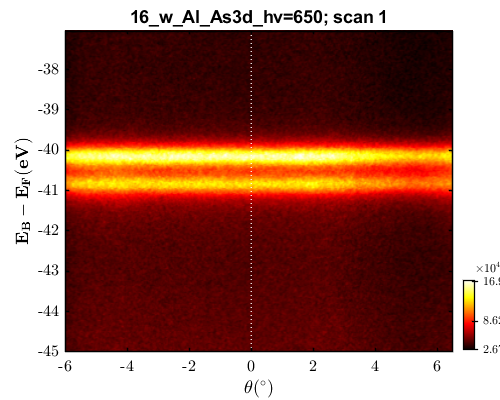

view_arpes_data(xps_dat{1});

**(B) Loading in the Fermi-Edge reference files**

file_names_ref      = {...
    '15_w_Al_As3d_hv=650_EF.h5',...
    '23_w_Al_As3d_hv=750_EF.h5',...
    '33_w_Al_As3d_hv=850_EF.h5',...
    '41_w_Al_As3d_hv=950_EF.h5',...
    '49_w_Al_As3d_hv=1050_EF.h5',...
    '59_w_Al_As3d_hv=1150_EF.h5',...
    };
xps_ref = {};
for i = 1:length(file_names_ref); xps_ref{i} = load_adress_data(file_names_ref{i}, data_path); end

Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...


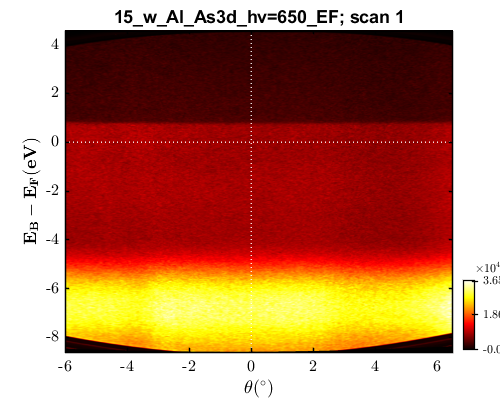

view_arpes_data(xps_ref{1});

**(C) Binding energy alignment to the reference data**

help align_energy;

  dataStr = align_energy(dataStr, align_args, dataStr_ref, plot_result)
    This is a function that will align the 'dataStr' ARPES data-structure 
    to the Fermi-level, VB or CB state. It operates using the
    AlignEF() function conditions, but can also load in a reference data file
    'dataStr_ref' that it will use as the energy reference.
 
    REQ. FUNCTIONS:
    -   [xField, yField, zField, dField] = find_data_fields(dataStr);
    -   [EAlign, EF, Fail] = AlignEF(Data, ECorr [,eWin] [,dEWin] [,dESmooth] [,feat]);
 
    IN:
    -   dataStr:            data structure of the ARPES data.
    -   align_args:         {1×6} cell of {Type,Scans,eWin, dEWin, dESmooth, feat}.
                                Type:       "global"
                                          	"align2ref"
                                        	"align2ref-perchannel"
                                        	"fit2ef" || "fit2ef-95%" (default 95% window size)
                                    

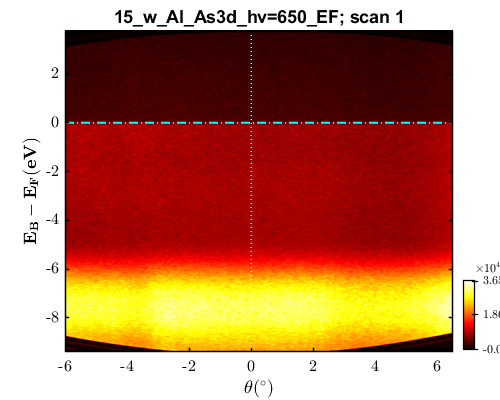

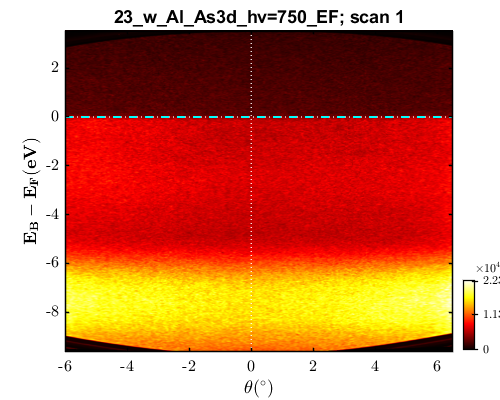

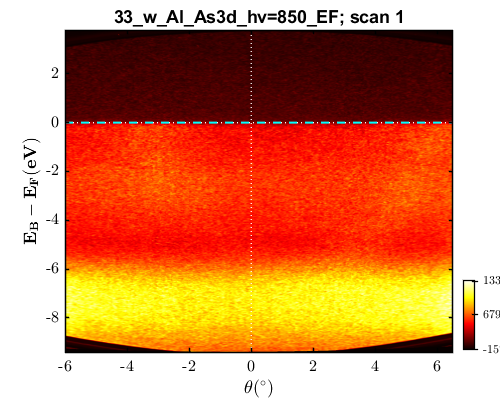

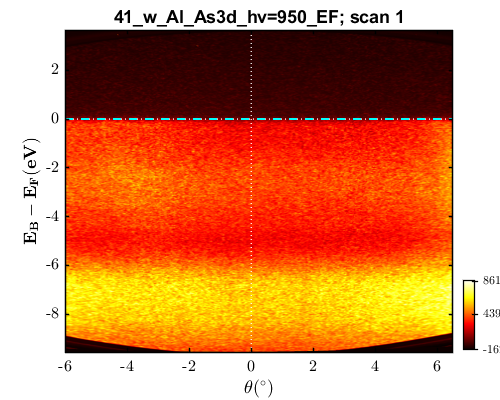

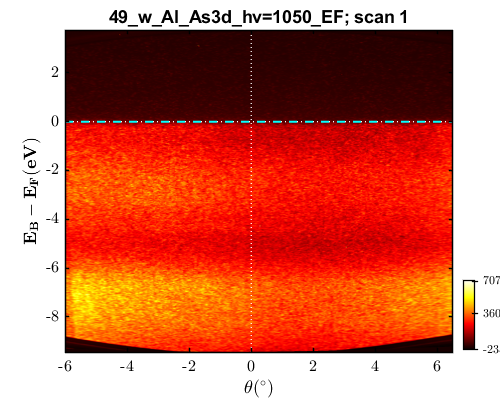

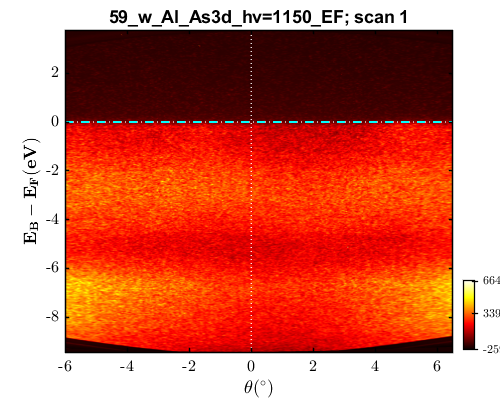

% (1) AUTOMATIC COARSE ALIGNMENT TO THE EDGE OF THE REFERENCE
% -- Coarse alignment of the energy
alignType   = "align2ref";
scan_indxs	= [];
eWin        = 0.00;
dEWin       = 4.00;
dESmooth    = [];
feat        = 'edge';
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(xps_dat)
    xps_dat{i}  = align_energy(xps_dat{i}, align_args, xps_ref{i}); 
    xps_ref{i}.raw_eb = xps_ref{i}.raw_eb - xps_dat{i}.eb_shifts{1};
    view_arpes_data(xps_ref{i}); line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--'); 
end

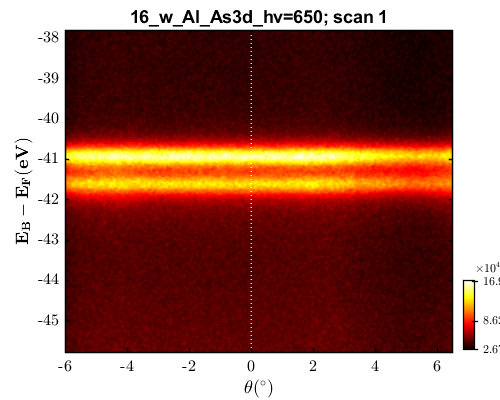

% (2) FITTING TO THE FDD WITH FINE ALIGNMENT
alignType   = "fit2ef-25%"; 
scan_indxs	= [];
eWin        = 0.00;
dEWin       = 0.50;
dESmooth    = [];
feat        = 'edge';
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(xps_dat)
    xps_dat{i}  = align_energy(xps_dat{i}, align_args, xps_ref{i}, 0); 
end
view_arpes_data(xps_dat{1});
line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--'); 

**(D) Extracting the angle-integrated XPS spectra**

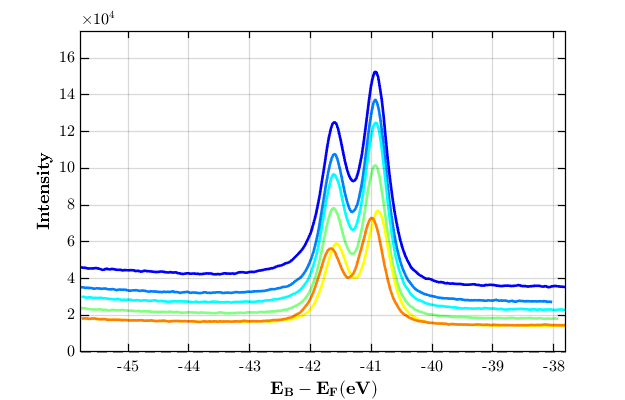

for i = 1:length(xps_dat)
    cutWin      = 0.95*[min(xps_dat{i}.raw_tht(:)), max(xps_dat{i}.raw_tht(:))];      % Integration window of the cut to be made.
    xps_args    = {cutWin};
    [xps_dat{i}, ~] = pes_extract_data(xps_dat{i}, xps_args, 0); 
end
view_pes_data(xps_dat);

**(E) Extracting the principal peak position**

1) x = -40.93 eV, y = 152891.96 


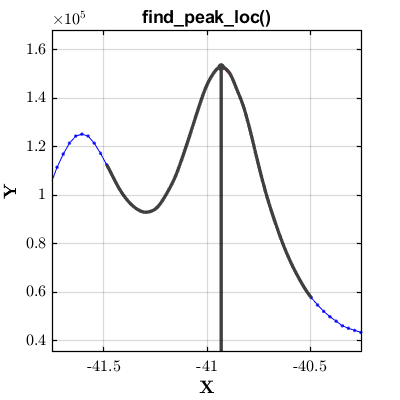

% -- Extracting the energy and intensity of the peak positions
xWin       = -41 + 0.5*[-1,1];
for i = 1:length(xps_dat)
    if i == 1;  [xps_dat{i}.peak_loc, xps_dat{i}.peak_int] = find_peak_loc(xps_dat{i}.xdat, xps_dat{i}.ydat, xWin, 'spline', 1); 
    else;       [xps_dat{i}.peak_loc, xps_dat{i}.peak_int] = find_peak_loc(xps_dat{i}.xdat, xps_dat{i}.ydat, xWin, 'spline', 0); 
    end
end

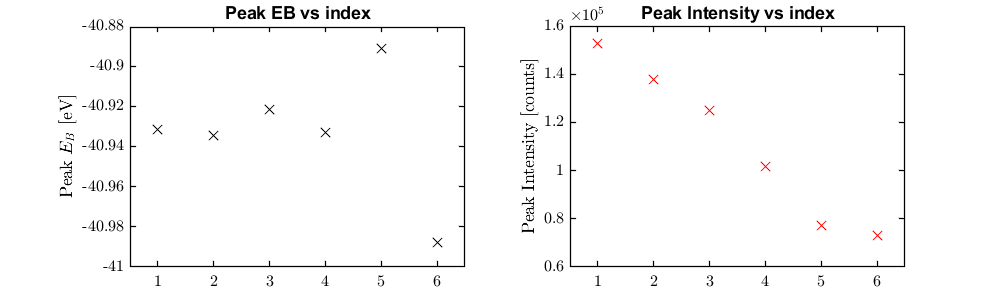

% -- Plotting the comparison
fig1 = figure();
fig1.Position(3) = 2.0*500;
fig1.Position(4) = 1.0*300;
% -- Plotting the Peak Eb position vs Photon Energy
subplot(121); hold on;
for i = 1:length(xps_dat); plot(i, xps_dat{i}.peak_loc, 'kx-', 'markersize', 10); end
gca_props(); xlim([0.5, length(xps_dat)+0.5]);
title('Peak EB vs index');
ylabel('Peak $$E_{B}$$ [eV]', 'interpreter', 'latex');
% -- Plotting the Peak Intensity vs Photon Energy
subplot(122); hold on;
for i = 1:length(xps_dat); plot(i, xps_dat{i}.peak_int, 'rx-', 'markersize', 10); end
gca_props(); xlim([0.5, length(xps_dat)+0.5]);
title('Peak Intensity vs index');
ylabel('Peak Intensity [counts]', 'interpreter', 'latex');

**(F) Normalising the XPS data**

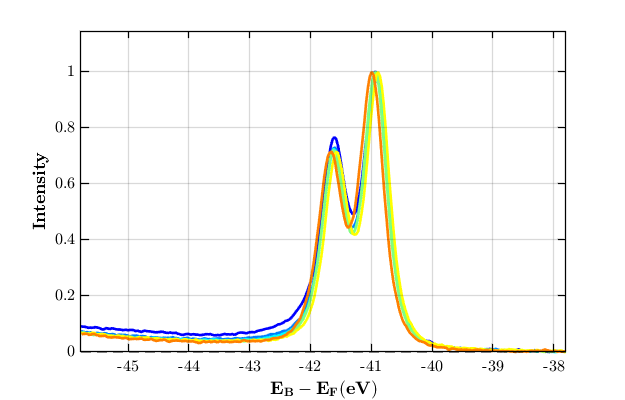

for i = 1:length(xps_dat)
    eWin            = xps_dat{i}.peak_loc;      % approximate Eb position of a peak in the spectrum to normalise to.
    dEWin           = 1.0;                      % can be empty []. Single, constant value that defines the width of the approximate Eb position
    norm_args       = {eWin, dEWin};
    xps_dat{i}.ydat = pes_norm2peak(xps_dat{i}.xdat, xps_dat{i}.ydat, norm_args, 0);
end
view_pes_data(xps_dat);

**(G) Cropping the XPS data**

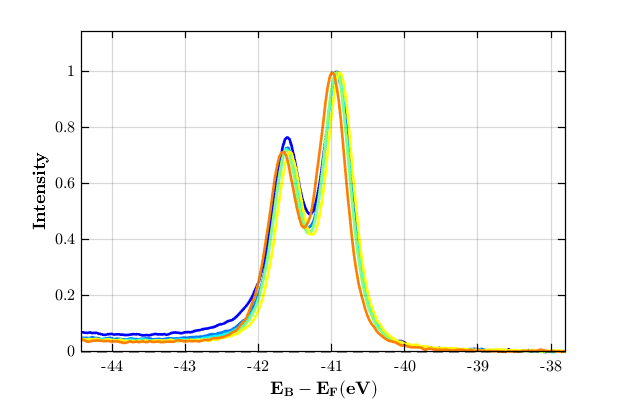

ebLims = xps_dat{1}.peak_loc + [-3.5, 3.5];
for i = 1:length(xps_dat)
    [~, xps_dat{i}.xdat, xps_dat{i}.ydat] = data_crop2D([], xps_dat{i}.xdat, xps_dat{i}.ydat, [], ebLims);
end
view_pes_data(xps_dat);

**(H) View all the XPS data to be fitted**

view_pes_data(xps_dat);

# **(2.1) FitCL2PEAK: Extracting the Peak Position of the XPS data**

**(A) Initialising the XPS data to be fitted**

xps_fit               = struct();
xps_fit.FileName      = file_names;
xps_fit.repeats       = length(xps_dat);
xps_fit.data          = xps_dat;

**(B) Peak Position Determintion**

1) x = -40.93 eV, y = 1.00 


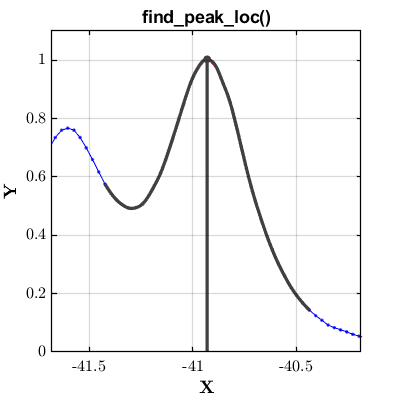

xWin       = xps_fit.data{1}.peak_loc + 0.5*[-1,1];
xps_fit.ECL = []; xps_fit.ECL_int = [];
for i = 1:length(xps_dat)
    if i == 1;  [xps_fit.ECL(i), xps_fit.ECL_int(i)] = find_peak_loc(xps_dat{i}.xdat, xps_dat{i}.ydat, xWin, 'spline', 1); 
    else;       [xps_fit.ECL(i), xps_fit.ECL_int(i)] = find_peak_loc(xps_dat{i}.xdat, xps_dat{i}.ydat, xWin, 'spline', 0); 
    end
end

**(C) Finding the best estimate of ECL across the dataset**

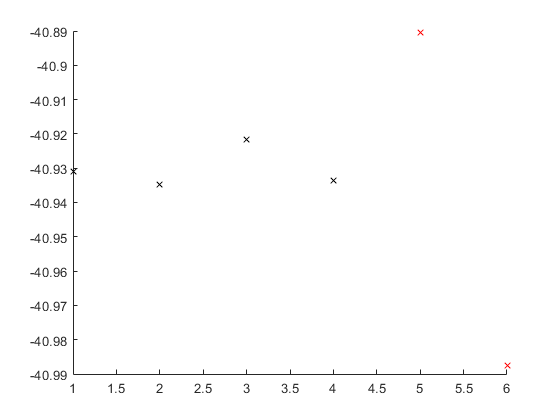

ECL     = zeros(1,length(xps_fit.ECL)); 
for i = 1:length(xps_dat)
    ECL(i)      = xps_fit.ECL(i);
end
% -- Isolating any potential outliers
XX              = 1:length(ECL);
TF              = isoutlier(ECL); % TF(1:end) = 0;
XX_adj{1}       = XX(~TF);
XX_adj{2}       = XX(TF);
ECL_adj{1}      = ECL(~TF);
ECL_adj{2}      = ECL(TF);
% -- Plotting the result of outlier analysis
figure(); hold on;
plot(XX_adj{1}, ECL_adj{1}, 'kx');
plot(XX_adj{2}, ECL_adj{2}, 'rx');

% -- Redefining ECL
ECL            = ECL(~TF);
% -- Final assignments
ECL_mu         = mean(ECL)

ECL_mu = -40.9302

ECL_3sig       = 3*std(ECL)

ECL_3sig = 0.0176

**(D) -  Saving the SXARPES data & fit results**

-> saved data : 


dataStr = struct with fields:
             filename: "id20210603_M0322211_hvAs3d_FitCL2PEAK"
           fit_method: "FitCL2PEAK"
          beamtime_id: "20210603"
           dataset_id: "GaAs Etch Stop Set"
            sample_id: "M03-22-21.1"
    sample_stack_info: "AlOx [2.5 nm] / Al [4 nm] / GaAs [2ML] / InAlAs(10pc) [8.4 nm] "
    repeated_measures: 6
             xps_data: {1×6 cell}
                  ECL: [-40.9309 -40.9346 -40.9218 -40.9337]
               ECL_mu: -40.9302
             ECL_3sig: 0.0176

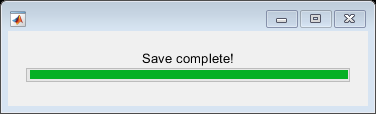

% Defining the MATLAB data structure
id20210603_M0322211_hvAs3d_FitCL2PEAK                         = struct();
% - Measurement / Sample Information
id20210603_M0322211_hvAs3d_FitCL2PEAK.filename                = filename+"_"+"FitCL2PEAK";
id20210603_M0322211_hvAs3d_FitCL2PEAK.fit_method              = "FitCL2PEAK";
id20210603_M0322211_hvAs3d_FitCL2PEAK.beamtime_id             = beamtime_id;
id20210603_M0322211_hvAs3d_FitCL2PEAK.dataset_id              = dataset_id;
id20210603_M0322211_hvAs3d_FitCL2PEAK.sample_id               = sample_id;
id20210603_M0322211_hvAs3d_FitCL2PEAK.sample_stack_info       = sample_stack_info;
% - Best Fit XPS Results
% -- XPS data and corresponding best fits
id20210603_M0322211_hvAs3d_FitCL2PEAK.repeated_measures       = xps_fit.repeats;
id20210603_M0322211_hvAs3d_FitCL2PEAK.xps_data                = xps_fit.data;
% -- ECL estimates & measurement uncertainty
id20210603_M0322211_hvAs3d_FitCL2PEAK.ECL                     = ECL;
id20210603_M0322211_hvAs3d_FitCL2PEAK.ECL_mu                  = ECL_mu;
id20210603_M0322211_hvAs3d_FitCL2PEAK.ECL_3sig                = ECL_3sig;
% - Saving the data
save_adress_data(id20210603_M0322211_hvAs3d_FitCL2PEAK, save_path + id20210603_M0322211_hvAs3d_FitCL2PEAK.filename);

id20210603_M0322211_hvAs3d_FitCL2PEAK

id20210603_M0322211_hvAs3d_FitCL2PEAK = struct with fields:
             filename: "id20210603_M0322211_hvAs3d_FitCL2PEAK"
           fit_method: "FitCL2PEAK"
          beamtime_id: "20210603"
           dataset_id: "GaAs Etch Stop Set"
            sample_id: "M03-22-21.1"
    sample_stack_info: "AlOx [2.5 nm] / Al [4 nm] / GaAs [2ML] / InAlAs(10pc) [8.4 nm] "
    repeated_measures: 6
             xps_data: {1×6 cell}
                  ECL: [-40.9309 -40.9346 -40.9218 -40.9337]
               ECL_mu: -40.9302
             ECL_3sig: 0.0176

**(E) -  Saving the corresponding figure & text file with fit results**

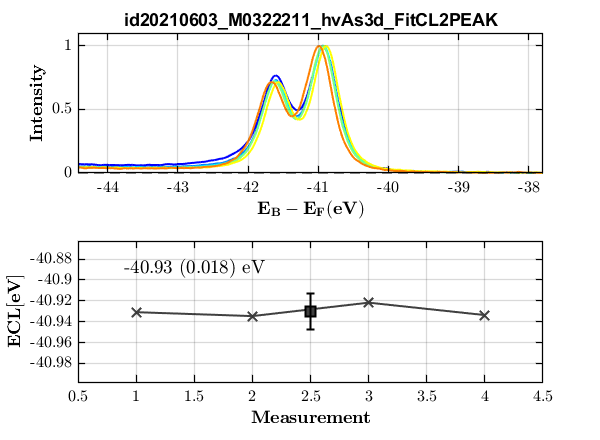

% Initialising the figure
pp  = plot_props();
fig = figure();
fig.Position(3) = 1.50*pp.fig4x4(1);
fig.Position(4) = 1.10*pp.fig4x4(2);

% (1) PLOTTING THE XPS DATA
subplot(2,1,1); hold on;
% -- Plotting all of the curve components
cols = jet(length(xps_fit.data)+1);
for i = 1:length(xps_fit.data)
    plot(id20210603_M0322211_hvAs3d_FitCL2PEAK.xps_data{i}.xdat, id20210603_M0322211_hvAs3d_FitCL2PEAK.xps_data{i}.ydat, 'k-', 'color', cols(i,:), 'linewidth', 1.5);
end
% - Formatting the figure
gca_props(); grid on;
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Intensity$$', 'Interpreter', 'latex');
axis([...
    min(id20210603_M0322211_hvAs3d_FitCL2PEAK.xps_data{1}.xdat(:)), max(id20210603_M0322211_hvAs3d_FitCL2PEAK.xps_data{1}.xdat(:)),...
    min(id20210603_M0322211_hvAs3d_FitCL2PEAK.xps_data{1}.ydat(:)), 1.1*max(id20210603_M0322211_hvAs3d_FitCL2PEAK.xps_data{1}.ydat(:))]);
title(id20210603_M0322211_hvAs3d_FitCL2PEAK.filename, 'interpreter', 'none');

% (3) PLOTTING ECL VS MEASUREMENT NUMBER
subplot(2,1,2); hold on;
% Plotting ECL vs measurement number
XX = 1:length(id20210603_M0322211_hvAs3d_FitCL2PEAK.ECL);
plot(XX, id20210603_M0322211_hvAs3d_FitCL2PEAK.ECL, 'kx-', 'color', pp.col.fit{1}, 'markerfacecolor', pp.col.fit{1}, 'linewidth', 1.5,'markersize', 10);
errorbar(mean(XX(:)), id20210603_M0322211_hvAs3d_FitCL2PEAK.ECL_mu, id20210603_M0322211_hvAs3d_FitCL2PEAK.ECL_3sig, id20210603_M0322211_hvAs3d_FitCL2PEAK.ECL_3sig, 0, 0, 'ks-',...
    'color', [0 0 0], 'markerfacecolor', pp.col.fit{1}, 'markersize', 10, 'linewidth', 1.5);
% -- Formatting the figure
grid on; gca_props();
axis([0.5, max(XX)+0.5, id20210603_M0322211_hvAs3d_FitCL2PEAK.ECL_mu-id20210603_M0322211_hvAs3d_FitCL2PEAK.ECL_3sig-0.05, id20210603_M0322211_hvAs3d_FitCL2PEAK.ECL_mu+id20210603_M0322211_hvAs3d_FitCL2PEAK.ECL_3sig+0.05]);
% xlabel('$$ \bf  Measurement $$', 'Interpreter', 'latex');
ylabel('$$ \bf  ECL [eV]  $$', 'Interpreter', 'latex');
ECL_str = string(round(id20210603_M0322211_hvAs3d_FitCL2PEAK.ECL_mu,3)) + " (" + string(round(id20210603_M0322211_hvAs3d_FitCL2PEAK.ECL_3sig,3)) + ") eV";
text(0.1,0.8,ECL_str,'Interpreter',"latex",'Units',"normalized",'FontSize',14);
xlabel('$$ \bf  Measurement $$', 'Interpreter', 'latex');

% (5) SAVING THE FIGURE
print(save_path + id20210603_M0322211_hvAs3d_FitCL2PEAK.filename,'-dpng', '-r500');


% (6) SAVING A TEXT FILE
% -- Creating an information string
info = "";
info = info + sprintf("Filename: \t\t %s \n",             id20210603_M0322211_hvAs3d_FitCL2PEAK.filename);
info = info + sprintf("Fit Method: \t %s \n",           id20210603_M0322211_hvAs3d_FitCL2PEAK.fit_method);
info = info + sprintf("Sample ID: \t\t %s \n",            id20210603_M0322211_hvAs3d_FitCL2PEAK.sample_id);
info = info + sprintf("Sample stack: \t %s \n",         id20210603_M0322211_hvAs3d_FitCL2PEAK.sample_stack_info);
info = info + sprintf("Beamtime ID: \t %s \n",          id20210603_M0322211_hvAs3d_FitCL2PEAK.beamtime_id);
info = info + sprintf("Repeats: \t\t %i \n",              id20210603_M0322211_hvAs3d_FitCL2PEAK.repeated_measures);
info = info + sprintf("ECL: \t\t\t %.3f (%.3f) eV \n",    id20210603_M0322211_hvAs3d_FitCL2PEAK.ECL_mu, id20210603_M0322211_hvAs3d_FitCL2PEAK.ECL_3sig);
info = info + sprintf("Notes: \t\t %s", measurement_notes);
fprintf(info);

Filename: 		 id20210603_M0322211_hvAs3d_FitCL2PEAK 
Fit Method: 	 FitCL2PEAK 
Sample ID: 		 M03-22-21.1 
Sample stack: 	 AlOx [2.5 nm] / Al [4 nm] / GaAs [2ML] / InAlAs(10pc) [8.4 nm]  
Beamtime ID: 	 20210603 
Repeats: 		 6 
ECL: 			 -40.930 (0.018) eV 
Notes: 		 

% -- Writing the string to a text file
fileID = fopen(char(save_path + id20210603_M0322211_hvAs3d_FitCL2PEAK.filename + ".txt"),'w');
fprintf(fileID,info);
fclose(fileID);

# **(2.2) FitCL2NC: XPS Curve Fitting to find the Peak Position**

**(A) Initialising the XPS data to be fitted**

xps_fit               = struct();
xps_fit.FileName      = file_names;
xps_fit.repeats       = length(xps_dat);
xps_fit.data          = xps_dat;
xps_fit.model         = modelStr;

**(B) Defining the initial conditions & bounds for the model fit**

% DEFINING THE TYPES OF CURVES TO BE USED
help PESCurve;

  ydat = PESCurve(xdat, cTYPE, BE, INT, FWHM, MR, LSE, LSI, LSW, ASY, plot_result)
    Function that evaluates a generic photoelectron spectroscopy (PES)
    curve, by defining a primary (P) and spin-orbit split (SOS) component.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:    	N×1 column vector of the input domain (binding energy for XPS)
    -   cTYPE:      type of curve to use for fitting. Default: "sGLA" ("sGLA", "pGLA", "sGL", "pGL", "G", "L", "DS")
    -   BE:      	scalar of the binding energy of PE curve.
    -   INT:    	scalar of the peak intensity of PE curve.
    -   FWHM:     	scalar of the FWHM of the PE curve.
    -   MR:     	scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
    -   LSE:     	scalar of the binding energy of spin-orbit split PE curve.
    -   LSI:     	scalar of the branching ratio of spin-orbit split PE curve.
    -   LSW:     	scalar of the additional lorentzian width of spin-orbit split PE curve.
    -   

cTYPE   = ["sGLA"];  % type of curve to use for fitting. Default: "sGLA" ("pGLA", "DS")
% 1.1 - DEFINING THE INITIAL CONDITIONS OF THE XPS COMPONENTS
BE      = [-40.882];        % scalar of the binding energy of PE curve. Each new row gives a new BE component. Make sure sizes are all consistent.
INT     = [1.07];          % scalar of the peak intensity of PE curve.
FWHM    = [0.48];          % scalar of the FWHM of the PE curve.
MR      = [0.69];          % scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
LSE     = [-0.69];         % scalar of the binding energy of spin-orbit split PE curve.
LSI     = [0.66];          % scalar of the branching ratio of spin-orbit split PE curve.
LSW     = [0.00];          % scalar of the additional lorentzian width of spin-orbit split PE curve.
ASY     = [0.00];          % scalar of the PE curve asymmetry parameter (usually for metallic systems).
iparams{1} = [BE, INT, FWHM, MR, LSE, LSI, LSW, ASY]; 
iparams{1}

ans =   -40.8700    1.0700    0.4800    0.6900   -0.6900    0.6600         0         0


% 1.2 - DEFINING THE UNCERTAINTIES IN THE FIT PARAMETERS
% -- Lower bounds
iparams{2} = iparams{1}; 
iparams{2}(:,1) = iparams{1}(:,1) - 0.25;
iparams{2}(:,2) = iparams{1}(:,2) - 1.00;
iparams{2}(:,3) = iparams{1}(:,3) - 0.25; 
iparams{2}(:,4) = iparams{1}(:,4) - 0.25; 
iparams{2}(:,5) = iparams{1}(:,5) - 0.15; 
iparams{2}(:,6) = iparams{1}(:,6) - 0.15; 
iparams{2}(:,7) = iparams{1}(:,7) - 0.00; 
iparams{2}(:,8) = iparams{1}(:,8) - 0.00;
iparams{2}

ans =   -41.1200    0.0700    0.2300    0.4400   -0.8400    0.5100         0         0


% -- Upper bounds
iparams{3}      = iparams{1}; 
iparams{3}(:,1) = iparams{1}(:,1) + 0.25; 
iparams{3}(:,2) = iparams{1}(:,2) + 0.50;
iparams{3}(:,3) = iparams{1}(:,3) + 0.25; 
iparams{3}(:,4) = iparams{1}(:,4) + 0.25; 
iparams{3}(:,5) = iparams{1}(:,5) + 0.15; 
iparams{3}(:,6) = iparams{1}(:,6) + 0.15; 
iparams{3}(:,7) = iparams{1}(:,7) + 0.00; 
iparams{3}(:,8) = iparams{1}(:,8) + 0.00;
iparams{3}

ans =   -40.6200    1.5700    0.7300    0.9400   -0.5400    0.8100         0         0



% 2.1 - DEFINING THE BACKGROUND PARAMETERS
help PESBackground;

  [roi_xdat, roi_ydat, roi_bgrnd] = PESBackground(xdat, ydat, bTYPE, LHS, RHS, BGR, ARGS, plot_result)
    Function that evaluates the background associated with 1D data or
    photoelectron spectroscopy (PES) data acquired at the ADRESS beamline, 
    SLS. The background type can be defined over a given region of interest
    (ROI). 
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:           N×1 column vector of the input domain (binding energy for PES).
    -   ydat:           N×1 column vector of the intensity range (intensity for PES).
    -   bTYPE:          string of the type of background to use for fitting. {Default: "Poly" ("none", "Poly", "Shir", "LinShir", "StepFDDGpL", "StepFDDGsL")}
    -   LHS:            scalar of the LHS x-axis START position of the ROI. {Default: 25th percentile.}
    -   RHS:            scalar of the RHS x-axis END position of the ROI. {Default: 75th percentile.}
    -   BGR:            scalar for a constant y-axis background to be 

bTYPE   = "shir";       % type of background to use for fitting. Default: "Poly" ("none", "Shir", "LinShir")
LHS     = -43.5;      % scalar of the START point on the LHS for background
RHS     = -38.5;      % scalar of the END point on the RHS for background
BGR     = 0.00;      % scalar for a constant background to be included in the fit
ibgrnd{1} = [LHS, RHS, BGR]; 
ibgrnd{1}

ans =   -43.5000  -38.5000         0


% 2.2 - DEFINING THE UNCERTAINTY IN THE BACKGROUND PARAMETERS
% -- Lower bounds
ibgrnd{2} = abs(0.0.*ibgrnd{1}); 
ibgrnd{2}(:,1) = ibgrnd{1}(:,1) - 0.00;
ibgrnd{2}(:,2) = ibgrnd{1}(:,2) - 0.00;
ibgrnd{2}(:,3) = ibgrnd{1}(:,3) - 0.05;
ibgrnd{2}

ans =   -43.5000  -38.5000   -0.0500


% -- Upper bounds
ibgrnd{3} = abs(0.0.*ibgrnd{1}); 
ibgrnd{3}(:,1) = ibgrnd{1}(:,1) + 0.00;
ibgrnd{3}(:,2) = ibgrnd{1}(:,2) + 0.00;
ibgrnd{3}(:,3) = ibgrnd{1}(:,3) + 0.05;
ibgrnd{3}

ans =   -43.5000  -38.5000    0.0500


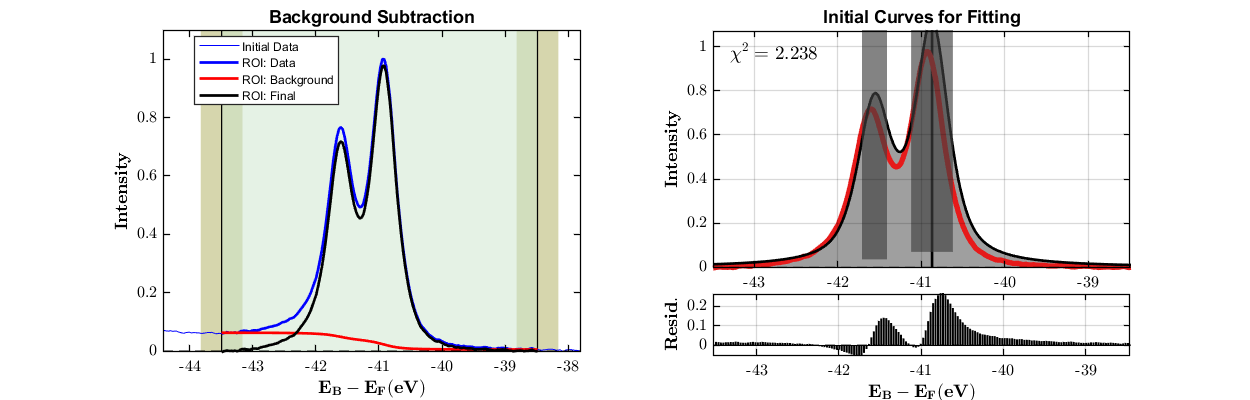

% 2.3 - DEFINING THE BACKGROUND ARGUMENTS
ibgrnd{4} = {};

% 3 - Preview the initial conditions of the model vs data fit
pes2ncurve_view_init(xps_fit.data{1}, cTYPE, iparams, bTYPE, ibgrnd);

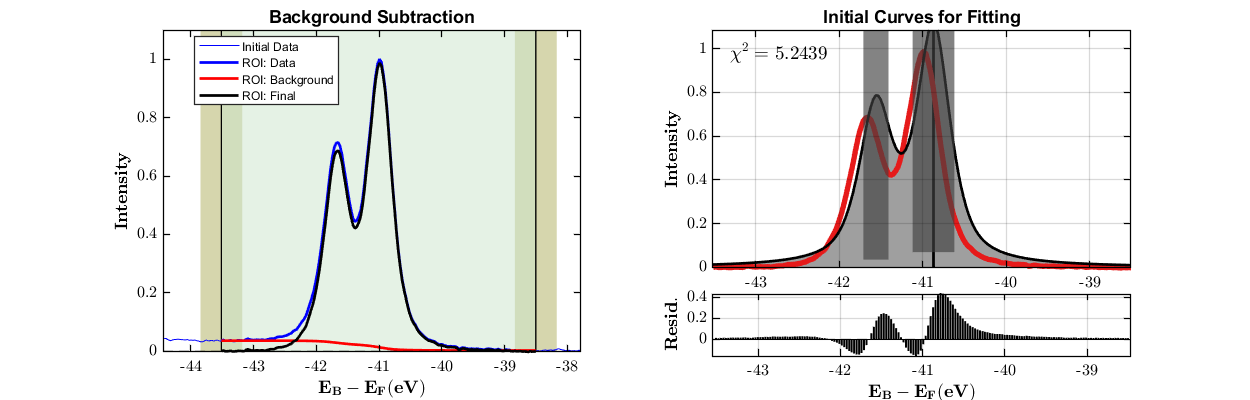

pes2ncurve_view_init(xps_fit.data{end}, cTYPE, iparams, bTYPE, ibgrnd);

**(C) Execute XPS fitting algorithm**

solve_type  = "lsqcurvefit";
for i = 1:length(xps_fit.data)
    fprintf("Run %i / %i", i, length(xps_fit.data));
    % -- Solve the fit
    xps_fit.fits{i} = pes2ncurve_solver(xps_fit.data{i}, cTYPE, iparams, bTYPE, ibgrnd, solve_type);
end

Run 1 / 6


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Run 2 / 6


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Run 3 / 6


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Run 4 / 6


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Run 5 / 6


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Run 6 / 6


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


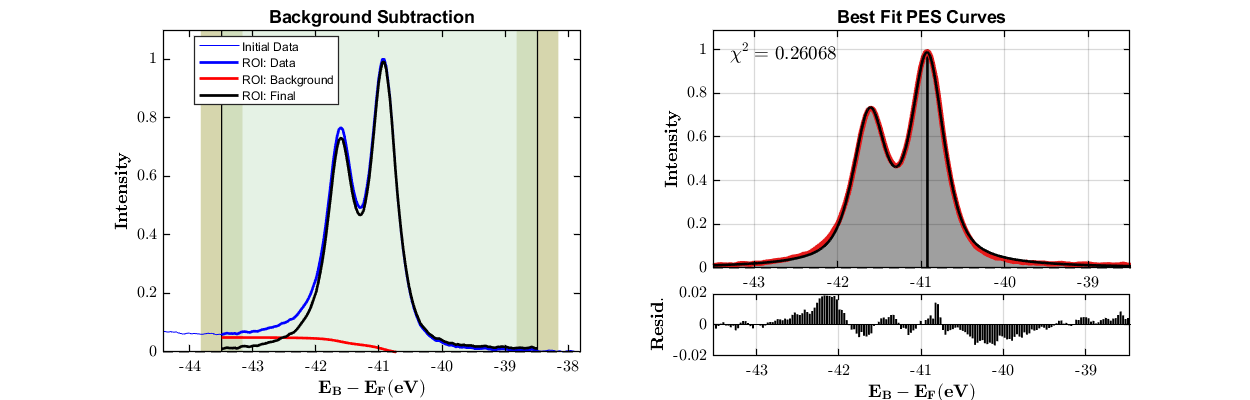

pes2ncurve_view_fit(xps_fit.fits{1});

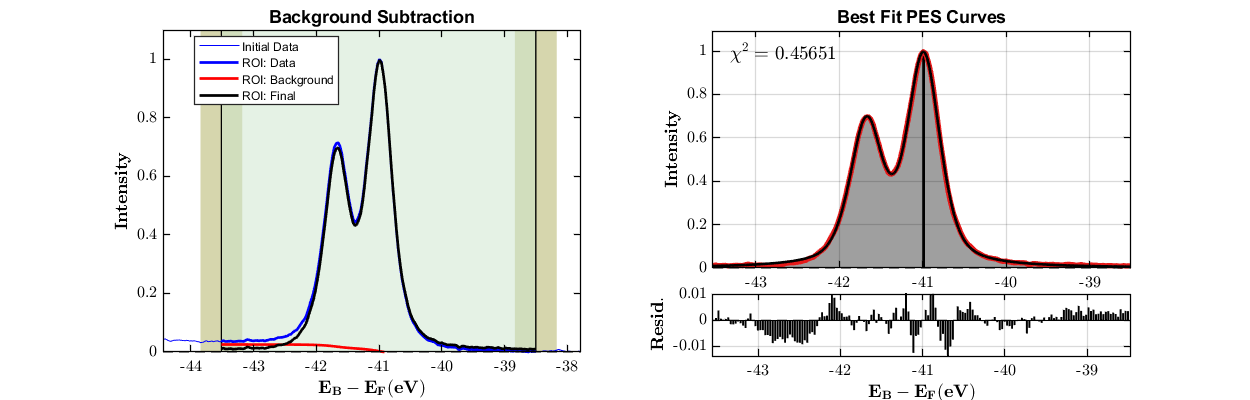

pes2ncurve_view_fit(xps_fit.fits{end});

**(D) Finding the best estimate of ECL across the dataset**

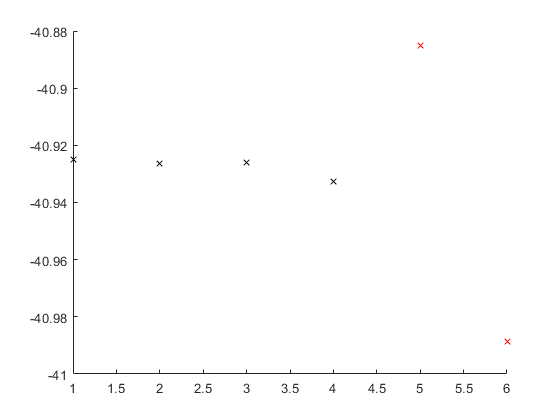

ECL = []; CHISQ = [];
for i = 1:length(xps_fit.fits)
    ECL(i)      = xps_fit.fits{i}.BE(1);
    CHISQ(i)    = xps_fit.fits{i}.CHISQ;
end
% Isolating any potential outliers
XX              = 1:length(ECL);
TF              = isoutlier(ECL); % TF(1:end) = 0;
DCL_adj{1}      = ECL(~TF);
DCL_adj{2}      = ECL(TF);
XX_adj{1}       = XX(~TF);
XX_adj{2}       = XX(TF);
% -- Plotting the result of outlier analysis
figure(); hold on;
plot(XX_adj{1}, DCL_adj{1}, 'kx');
plot(XX_adj{2}, DCL_adj{2}, 'rx');

% -- Redefining ECL and CHISQ
ECL         = ECL(~TF);
CHISQ       = CHISQ(~TF);
% -- Band-offset determination
ECL_mu      = mean(ECL)

ECL_mu = -40.9275

ECL_3sig    = 3*std(ECL)

ECL_3sig = 0.0106

CHISQ_mu    = mean(CHISQ)

CHISQ_mu = 0.6267

CHISQ_3sig  = 3*std(CHISQ)

CHISQ_3sig = 0.9350

**(E) -  Saving the XPS data & fit results**

-> saved data : 


dataStr = struct with fields:
             filename: "id20210603_M0322211_hvAs3d_FitCL2NC"
           fit_method: "FitCL2NC"
          beamtime_id: "20210603"
           dataset_id: "GaAs Etch Stop Set"
            sample_id: "M03-22-21.1"
    sample_stack_info: "AlOx [2.5 nm] / Al [4 nm] / GaAs [2ML] / InAlAs(10pc) [8.4 nm] "
           model_name: "2021-03_InAl10As_7nm_001-kpPoisson_pots-kp_spectra\"
           model_data: [1×1 struct]
    repeated_measures: 6
             xps_data: {1×6 cell}
             xps_fits: {1×6 cell}
                  ECL: [-40.9250 -40.9265 -40.9260 -40.9328]
               ECL_mu: -40.9275
             ECL_3sig: 0.0106
                CHISQ: [0.2607 0.4831 0.9404 0.8227]
             CHISQ_mu: 0.6267
           CHISQ_3sig: 0.9350

% Defining the MATLAB data structure
id20210603_M0322211_hvAs3d_FitCL2NC                          = struct();
% - Measurement / Sample Information
id20210603_M0322211_hvAs3d_FitCL2NC.filename                 = filename+"_"+"FitCL2NC";
id20210603_M0322211_hvAs3d_FitCL2NC.fit_method               = "FitCL2NC";
id20210603_M0322211_hvAs3d_FitCL2NC.beamtime_id              = beamtime_id;
id20210603_M0322211_hvAs3d_FitCL2NC.dataset_id               = dataset_id;
id20210603_M0322211_hvAs3d_FitCL2NC.sample_id                = sample_id;
id20210603_M0322211_hvAs3d_FitCL2NC.sample_stack_info        = sample_stack_info;
% - Theoretical Model Data
id20210603_M0322211_hvAs3d_FitCL2NC.model_name              = string(xps_fit.model.DirectoryName);
id20210603_M0322211_hvAs3d_FitCL2NC.model_data              = xps_fit.model;
% - Best Fit XPS Results for Aluminium covered sample
% -- XPS data and corresponding best fits
id20210603_M0322211_hvAs3d_FitCL2NC.repeated_measures       = xps_fit.repeats;
id20210603_M0322211_hvAs3d_FitCL2NC.xps_data                = xps_fit.data;
id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits                = xps_fit.fits;
% -- ECL estimates & measurement uncertainty
id20210603_M0322211_hvAs3d_FitCL2NC.ECL                     = ECL;
id20210603_M0322211_hvAs3d_FitCL2NC.ECL_mu                  = ECL_mu;
id20210603_M0322211_hvAs3d_FitCL2NC.ECL_3sig                = ECL_3sig;
% -- CHISQ estimates
id20210603_M0322211_hvAs3d_FitCL2NC.CHISQ                   = CHISQ;
id20210603_M0322211_hvAs3d_FitCL2NC.CHISQ_mu                = CHISQ_mu;
id20210603_M0322211_hvAs3d_FitCL2NC.CHISQ_3sig              = CHISQ_3sig;
% - Saving the data
save_adress_data(id20210603_M0322211_hvAs3d_FitCL2NC, save_path + id20210603_M0322211_hvAs3d_FitCL2NC.filename);

id20210603_M0322211_hvAs3d_FitCL2NC

id20210603_M0322211_hvAs3d_FitCL2NC = struct with fields:
             filename: "id20210603_M0322211_hvAs3d_FitCL2NC"
           fit_method: "FitCL2NC"
          beamtime_id: "20210603"
           dataset_id: "GaAs Etch Stop Set"
            sample_id: "M03-22-21.1"
    sample_stack_info: "AlOx [2.5 nm] / Al [4 nm] / GaAs [2ML] / InAlAs(10pc) [8.4 nm] "
           model_name: "2021-03_InAl10As_7nm_001-kpPoisson_pots-kp_spectra\"
           model_data: [1×1 struct]
    repeated_measures: 6
             xps_data: {1×6 cell}
             xps_fits: {1×6 cell}
                  ECL: [-40.9250 -40.9265 -40.9260 -40.9328]
               ECL_mu: -40.9275
             ECL_3sig: 0.0106
                CHISQ: [0.2607 0.4831 0.9404 0.8227]
             CHISQ_mu: 0.6267
           CHISQ_3sig: 0.9350

**(F) -  Saving the corresponding figure & text file with fit results**

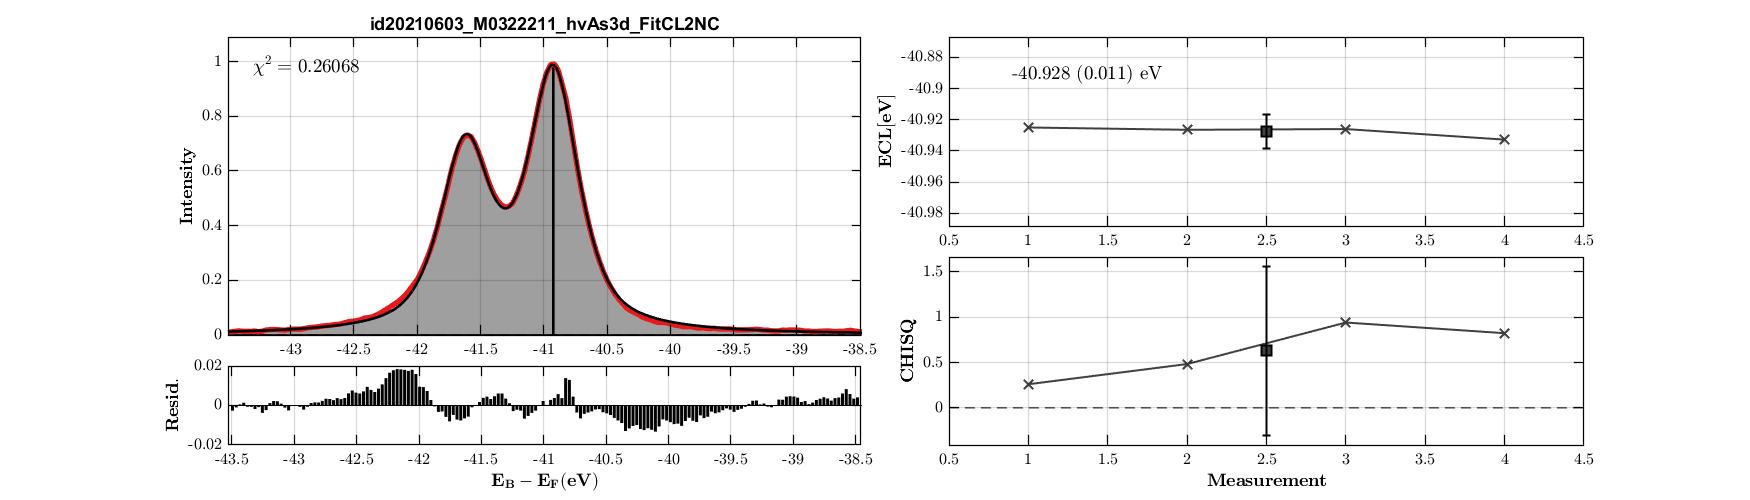

% Initialising the figure
pp  = plot_props();
fig = figure();
fig.Position(3) = 3.5*pp.fig5x4(1);
fig.Position(4) = 1.25*pp.fig5x4(2);
index = 1;

% (1) PLOTTING THE BEST FIT TO THE XPS DATA
subplot(4,4,[1,2,5,6,9,10]); hold on;
% -- Plotting all of the curve components
for i = 1:id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.nSTATES
    area(id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.XX, id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.cYY(:,i), 'FaceColor', pp.col.fit{i}, 'FaceAlpha', pp.falpha, 'EdgeAlpha', 0);
    plot(id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.XX, id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.cYY(:,i), 'k-', 'linewidth', 0.25);
end
% -- Plotting the curve component energy locations
for i = 1:id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.nSTATES
    if i == 1; lWidth = pp.llwidth; else; lWidth = pp.lwidth; end
    line([id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.cPARAMS(i,1), id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.cPARAMS(i,1)], [0, max(id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.cYY(:,i))],...
        'Color', [0 0 0], 'LineWidth', lWidth, 'Linestyle', '-');
end
% -- Plotting the experimental and fit spectra
plot(id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.X, id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.DB, 'k-', 'color', pp.col.dat{index}, 'linewidth', 2*pp.llwidth);
plot(id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.XX, id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.YY, 'k-', 'Color', pp.col.dat{2}, 'linewidth', 2*pp.lwidth);
% -- Add annotation for the quality of fit
text(0.04, 0.90, "$$ \chi^2 = $$ " + string(id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.CHISQ),...
    'interpreter', 'latex', 'fontsize', 14, 'color', 'k', 'Units','normalized');
% - Formatting the figure
gca_props(); grid on;
% xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Intensity$$', 'Interpreter', 'latex');
if min(id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.DB(:)) < id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.YY; min_y_val = min(id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.DB(:));
else; min_y_val = min(id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.YY(:)); 
end
if min_y_val > 0; min_y_val = 0; end
axis([min(id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.X(:)), max(id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.X(:)), min_y_val, 1.10*max(id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.DB(:))]);
title(id20210603_M0322211_hvAs3d_FitCL2NC.filename, 'interpreter', 'none');

% (2) PLOTTING THE CHI-SQUARED OF BEST FIT
subplot(4,4,[13,14]); hold on;
bar(id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.X, id20210603_M0322211_hvAs3d_FitCL2NC.xps_fits{index}.R, 'facecolor', [0 0 0]);
gca_props(); grid on;
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Resid. $$', 'Interpreter', 'latex');

% (3) PLOTTING ECL VS MEASUREMENT NUMBER
subplot(4,4,[3,4,7,8]); hold on;
% Plotting ECL vs measurement number
XX = 1:length(id20210603_M0322211_hvAs3d_FitCL2NC.ECL);
plot(XX, id20210603_M0322211_hvAs3d_FitCL2NC.ECL, 'kx-', 'color', pp.col.fit{index}, 'markerfacecolor', pp.col.fit{index}, 'linewidth', 1.5,'markersize', 10);
errorbar(mean(XX(:)), id20210603_M0322211_hvAs3d_FitCL2NC.ECL_mu, id20210603_M0322211_hvAs3d_FitCL2NC.ECL_3sig, id20210603_M0322211_hvAs3d_FitCL2NC.ECL_3sig, 0, 0, 'ks-',...
    'color', [0 0 0], 'markerfacecolor', pp.col.fit{index}, 'markersize', 10, 'linewidth', 1.5);
% -- Formatting the figure
grid on; gca_props();
axis([0.5, max(XX)+0.5, id20210603_M0322211_hvAs3d_FitCL2NC.ECL_mu-id20210603_M0322211_hvAs3d_FitCL2NC.ECL_3sig-0.05, id20210603_M0322211_hvAs3d_FitCL2NC.ECL_mu+id20210603_M0322211_hvAs3d_FitCL2NC.ECL_3sig+0.05]);
% xlabel('$$ \bf  Measurement $$', 'Interpreter', 'latex');
ylabel('$$ \bf  ECL [eV]  $$', 'Interpreter', 'latex');
ECL_str = string(round(id20210603_M0322211_hvAs3d_FitCL2NC.ECL_mu,3)) + " (" + string(round(id20210603_M0322211_hvAs3d_FitCL2NC.ECL_3sig,3)) + ") eV";
text(0.1,0.8,ECL_str,'Interpreter',"latex",'Units',"normalized",'FontSize',14);

% (4) PLOTTING CHISQ VS MEASUREMENT NUMBER
subplot(4,4,[11,12,15,16]); hold on;
% Plotting CHISQ vs measurement number
XX = 1:length(id20210603_M0322211_hvAs3d_FitCL2NC.CHISQ);
plot(XX, id20210603_M0322211_hvAs3d_FitCL2NC.CHISQ, 'kx-', 'color', pp.col.fit{index}, 'markerfacecolor', pp.col.fit{index}, 'linewidth', 1.5,'markersize', 10);
errorbar(mean(XX(:)), id20210603_M0322211_hvAs3d_FitCL2NC.CHISQ_mu, id20210603_M0322211_hvAs3d_FitCL2NC.CHISQ_3sig, id20210603_M0322211_hvAs3d_FitCL2NC.CHISQ_3sig, 0, 0, 'ks-',...
    'color', [0 0 0], 'markerfacecolor', pp.col.fit{index}, 'markersize', 10, 'linewidth', 1.5);
% -- Formatting the figure
grid on; gca_props();
axis([0.5, max(XX)+0.5, id20210603_M0322211_hvAs3d_FitCL2NC.CHISQ_mu-id20210603_M0322211_hvAs3d_FitCL2NC.CHISQ_3sig-0.1, id20210603_M0322211_hvAs3d_FitCL2NC.CHISQ_mu+id20210603_M0322211_hvAs3d_FitCL2NC.CHISQ_3sig+0.1]);
xlabel('$$ \bf  Measurement $$', 'Interpreter', 'latex');
ylabel('$$ \bf  CHISQ  $$', 'Interpreter', 'latex');

% (5) SAVING THE FIGURE
print(save_path + id20210603_M0322211_hvAs3d_FitCL2NC.filename,'-dpng', '-r500');


% (6) SAVING A TEXT FILE
% -- Creating an information string
info = "";
info = info + sprintf("Filename: \t\t %s \n",             id20210603_M0322211_hvAs3d_FitCL2NC.filename);
info = info + sprintf("Fit Method: \t %s \n",           id20210603_M0322211_hvAs3d_FitCL2NC.fit_method);
info = info + sprintf("Sample ID: \t\t %s \n",            id20210603_M0322211_hvAs3d_FitCL2NC.sample_id);
info = info + sprintf("Sample stack: \t %s \n",         id20210603_M0322211_hvAs3d_FitCL2NC.sample_stack_info);
info = info + sprintf("Beamtime ID: \t %s \n",          id20210603_M0322211_hvAs3d_FitCL2NC.beamtime_id);
info = info + sprintf("Repeats: \t\t %i \n",              id20210603_M0322211_hvAs3d_FitCL2NC.repeated_measures);
info = info + sprintf("ECL: \t\t\t %.3f (%.3f) eV \n",    id20210603_M0322211_hvAs3d_FitCL2NC.ECL_mu, id20210603_M0322211_hvAs3d_FitCL2NC.ECL_3sig);
info = info + sprintf("CHISQ: \t\t %.3f (%.3f) \n",     id20210603_M0322211_hvAs3d_FitCL2NC.CHISQ_mu, id20210603_M0322211_hvAs3d_FitCL2NC.CHISQ_3sig);
info = info + sprintf("Notes: \t\t %s", measurement_notes);
fprintf(info);

Filename: 		 id20210603_M0322211_hvAs3d_FitCL2NC 
Fit Method: 	 FitCL2NC 
Sample ID: 		 M03-22-21.1 
Sample stack: 	 AlOx [2.5 nm] / Al [4 nm] / GaAs [2ML] / InAlAs(10pc) [8.4 nm]  
Beamtime ID: 	 20210603 
Repeats: 		 6 
ECL: 			 -40.928 (0.011) eV 
CHISQ: 		 0.627 (0.935) 
Notes: 		 

% -- Writing the string to a text file
fileID = fopen(char(save_path + id20210603_M0322211_hvAs3d_FitCL2NC.filename + ".txt"),'w');
fprintf(fileID,info);
fclose(fileID);

# **(2.3) FitCL2BOFF: XPS Curve Fitting based on the boff**

**(A) Initialising the XPS data to be fitted**

xps_fit               = struct();
xps_fit.FileName      = file_names;
xps_fit.repeats       = length(xps_fit);
xps_fit.data          = xps_dat;
xps_fit.model         = modelStr;

**(B) Extracting the IMFP**

% - 1 - Extracting the material parameters from the materials database
material        = 'InAs';
material_props  = get_mpd_props(material);
Wfunc           = material_props.ELE_WFUNC;
% - 2 - Determination of the IMFP TPP-2M
hv = []; ke_dat = []; IMFP = [];
for i = 1:length(xps_fit.data) 
    hv(i)       = xps_fit.data{i}.hv;
    ke_dat(i)   = hv(i) - Wfunc;
    IMFP(i)     = eimfp_tpp2m_mpd(ke_dat(i), material);
end
hv
IMFP    = 0.1*IMFP          % - Convert IMFP to nm

**(C) Defining the initial conditions & bounds for the model fit**

help PESCurve_POT;
% DEFINING THE TYPES OF CURVES TO BE USED
cTYPE   = ["sGLA"];  % type of curve to use for fitting. Default: "sGLA" ("pGLA", "DS")
% 1.1 - DEFINING THE INITIAL CONDITIONS OF THE XPS COMPONENTS
MFP     = IMFP(1);             % scalar of the mean-free path of the emitted photoelectrons (either from optical, TPP-2M or fits) [nm]
BOFF    = -0.00;             % scalar of the band-offset [eV]

hv =          650         750         850         950        1050        1150


DCL     = [-40.91];         % scalar of the binding energy at BOFF = 0 of PE curve. Each new row gives a new BE component. Make sure sizes are all consistent.

IMFP =     1.3893    1.5415    1.6907    1.8371    1.9812    2.1232


INT     = [0.85];           % scalar of the peak intensity at BOFF = 0 of PE curve.
FWHM    = [0.48];           % scalar of the FWHM of the PE curve.
MR      = [0.69];           % scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.

  [ydat, ydat2D] = PESCurve_POT(xdat, cTYPE, BE, INT, FWHM, MR, LSE, LSI, LSW, ASY, MFP, ZPOT, EPOT, plot_result)
    Function that evaluates a generic photoelectron spectroscopy (PES)
    curve, by defining a primary (P) and spin-orbit split (SOS) component.
    A potential profile is also mapped onto the curve
    This type of curve should be used to fit near Fermi-edge EDC cuts.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:       N×1 column vector of the input domain (binding energy for PES).
    -   cTYPE:      type of curve to use for fitting. Default: "sGLA" ("sGLA", "pGLA", "sGL", "pGL", "G", "L", "DS")
    -   BE:      	scalar of the binding energy of PE curve.
    -   INT:    	scalar of the peak intensity of PE curve.
    -   FWHM:     	scalar of the FWHM of the PE curve.
    -   MR:     	scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
    -   LSE:     	scalar of the binding energy of spin-orbit split PE curve.
    -   LSI:     

LSE     = [-0.69];          % scalar of the binding energy of spin-orbit split PE curve.
LSI     = [0.66];           % scalar of the branching ratio of spin-orbit split PE curve.
LSW     = [0.00];           % scalar of the additional lorentzian width of spin-orbit split PE curve.
ASY     = [0.00];           % scalar of the PE curve asymmetry parameter (usually for metallic systems).
iparams{1} = [MFP, BOFF, DCL', INT', FWHM', MR', LSE', LSI', LSW', ASY']; 
iparams{1}
% 1.2 - DEFINING THE UNCERTAINTIES IN THE FIT PARAMETERS
n = length(cTYPE);
% -- Lower bounds
iparams{2} = iparams{1}; 
iparams{2}(1)           = iparams{1}(1) - 0.01;
iparams{2}(2)           = iparams{1}(2) - 0.50;
iparams{2}(3:3+n-1)     = iparams{1}(3:3+n-1) - 0.00;
iparams{2}(3+1*n:3+2*n-1) = iparams{1}(3+1*n:3+2*n-1) - 1.00;
iparams{2}(3+2*n:3+3*n-1) = iparams{1}(3+2*n:3+3*n-1) - 0.25; 

ans =   -40.8820    1.0700    0.4800    0.6900   -0.6900    0.6600         0         0


iparams{2}(3+3*n:3+4*n-1) = iparams{1}(3+3*n:3+4*n-1) - 0.25; 
iparams{2}(3+4*n:3+5*n-1) = iparams{1}(3+4*n:3+5*n-1) - 0.00; 
iparams{2}(3+5*n:3+6*n-1) = iparams{1}(3+5*n:3+6*n-1) - 0.00; 
iparams{2}(3+6*n:3+7*n-1) = iparams{1}(3+6*n:3+7*n-1) - 0.00; 
iparams{2}(3+7*n:3+8*n-1) = iparams{1}(3+7*n:3+8*n-1) - 0.00;
iparams{2}
% -- Upper bounds
iparams{3}      = iparams{1}; 
iparams{3}(1)           = iparams{1}(1) + 0.01;
iparams{3}(2)           = iparams{1}(2) + 0.50;
iparams{3}(3:3+n-1)       = iparams{1}(3:3+n-1) + 0.00;
iparams{3}(3+n:3+2*n-1)   = iparams{1}(3+1*n:3+2*n-1) + 1.00;

ans =   -41.1320    0.0700    0.2300    0.4400   -0.8400    0.5100         0         0


iparams{3}(3+2*n:3+3*n-1) = iparams{1}(3+2*n:3+3*n-1) + 0.25; 
iparams{3}(3+3*n:3+4*n-1) = iparams{1}(3+3*n:3+4*n-1) + 0.25; 
iparams{3}(3+4*n:3+5*n-1) = iparams{1}(3+4*n:3+5*n-1) + 0.00; 
iparams{3}(3+5*n:3+6*n-1) = iparams{1}(3+5*n:3+6*n-1) + 0.00; 
iparams{3}(3+6*n:3+7*n-1) = iparams{1}(3+6*n:3+7*n-1) + 0.00; 
iparams{3}(3+7*n:3+8*n-1) = iparams{1}(3+7*n:3+8*n-1) + 0.00;
iparams{3}

% 2.1 - DEFINING THE BACKGROUND PARAMETERS
bTYPE   = "Shir";       % type of background to use for fitting. Default: "Poly" ("none", "Shir", "LinShir")
LHS     = -43.5;      % scalar of the START point on the LHS for background

ans =   -40.6320    1.5700    0.7300    0.9400   -0.5400    0.8100         0         0


RHS     = -38.5;      % scalar of the END point on the RHS for background
BGR     = 0.00;      % scalar for a constant background to be included in the fit
ibgrnd{1} = [LHS, RHS, BGR]; 
ibgrnd{1}
% 2.2 - DEFINING THE UNCERTAINTY IN THE BACKGROUND PARAMETERS
% -- Lower bounds
ibgrnd{2} = abs(0.0.*ibgrnd{1}); 
ibgrnd{2}(:,1) = ibgrnd{1}(:,1) - 0.00;

ans =   -43.5000  -38.5000         0


ibgrnd{2}(:,2) = ibgrnd{1}(:,2) - 0.00;
ibgrnd{2}(:,3) = ibgrnd{1}(:,3) - 0.05;
ibgrnd{2}
% -- Upper bounds
ibgrnd{3} = abs(0.0.*ibgrnd{1}); 
ibgrnd{3}(:,1) = ibgrnd{1}(:,1) + 0.00;
ibgrnd{3}(:,2) = ibgrnd{1}(:,2) + 0.00;

ans =   -43.5000  -38.5000   -0.0500


ibgrnd{3}(:,3) = ibgrnd{1}(:,3) + 0.05;
ibgrnd{3}

% 3 - Preview the initial conditions of the model vs data fit
pes2boff_view_init(xps_fit.data{1}, xps_fit.model, cTYPE, iparams, bTYPE, ibgrnd);

**(D) Execute XPS fitting algorithm**

solve_type  = "lsqcurvefit";

ans =   -43.5000  -38.5000    0.0500


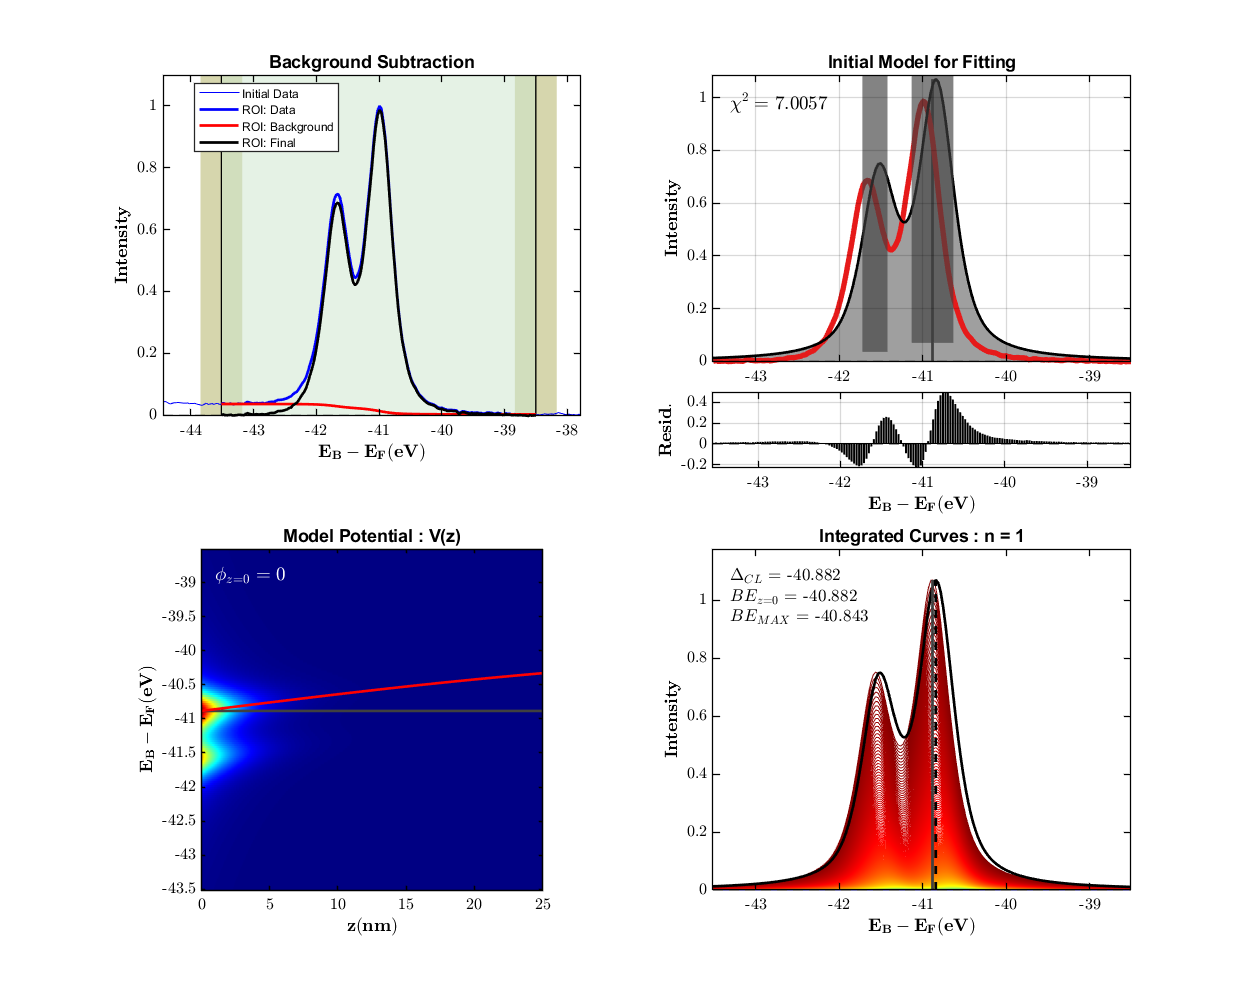

for i = 1:length(xps_fit.data)
    fprintf("Run %i / %i", i, length(xps_fit.data));
    % -- Setting the MFP
    iparams{1}(1) = IMFP(i); iparams{2}(1) = iparams{1}(1)- 0.01; iparams{3}(1) = iparams{1}(1) + 0.01;
    % -- Solve the fit

    xps_fit.fits{i} = pes2boff_solver(xps_fit.data{i}, xps_fit.model, cTYPE, iparams, bTYPE, ibgrnd, solve_type);
end
pes2boff_view_fit(xps_fit.fits{1}); xps_fit.fits{1}
pes2boff_view_fit(xps_fit.fits{end}); xps_fit.fits{end}

Run 1 / 6


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Run 2 / 6


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Run 3 / 6


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Run 4 / 6


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Run 5 / 6


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Run 6 / 6


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


**(E) Finding the best estimate of BOFF across the dataset**

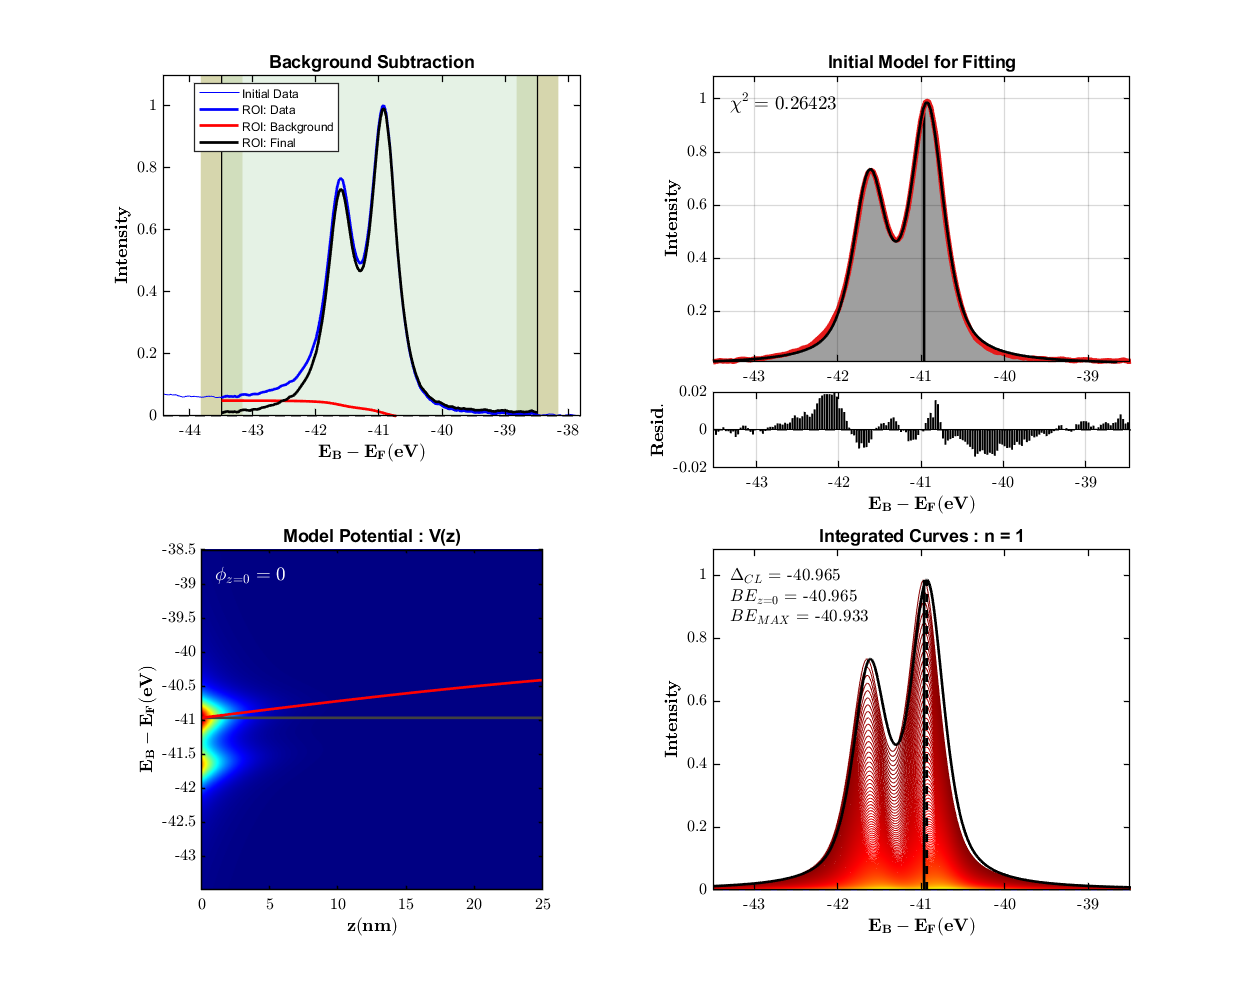

ans = struct with fields:
    solve_type: "lsqcurvefit"
         cTYPE: "sGLA"
       iparams: {1×3 cell}
         bTYPE: "shir"
        ibgrnd: {1×4 cell}
       nSTATES: 1
          xdat: [222×1 double]
          ydat: [222×1 double]
             X: [168×1 double]
             D: [168×1 double]
             M: [168×1 double]
             B: [168×1 double]
            DB: [168×1 double]
            MB: [168×1 double]
             R: [168×1 double]
         CHISQ: 0.2642
        MINFUN: 0.2642
           DoF: 7
       bPARAMS: [3×1 double]
           LHS: -43.5000
           RHS: -38.5000
           BGR: 0.0131
            XX: [1000×1 double]
            YY: [1000×1 double]
       cPARAMS: [-40.9652 0.9855 0.4623 0.6872 -0.6922 0.7120 0 0]
           cYY: [1000×1 double]
         potYY: [1000×400 double]
           DCL: -40.9652
           INT: 0.9855
          FWHM: 0.4623
            MR: 0.6872
           LSE: -0.6922
           LSI: 0.7120
           LSW: 0
           ASY: 0
       

DCL = []; MFP = []; BOFF = [];CHISQ = [];

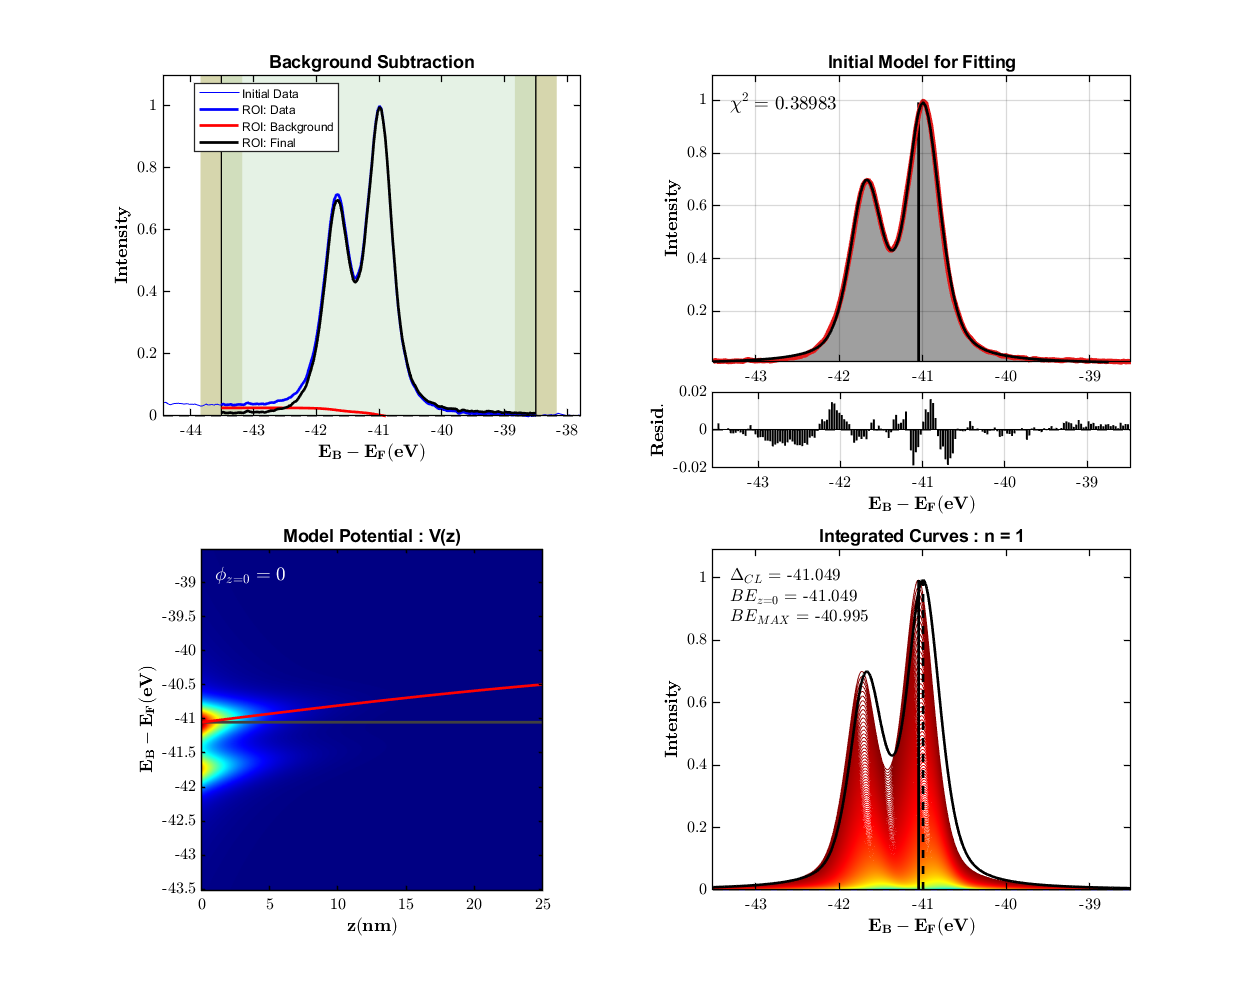

ans = struct with fields:
    solve_type: "lsqcurvefit"
         cTYPE: "sGLA"
       iparams: {1×3 cell}
         bTYPE: "shir"
        ibgrnd: {1×4 cell}
       nSTATES: 1
          xdat: [223×1 double]
          ydat: [223×1 double]
             X: [168×1 double]
             D: [168×1 double]
             M: [168×1 double]
             B: [168×1 double]
            DB: [168×1 double]
            MB: [168×1 double]
             R: [168×1 double]
         CHISQ: 0.3898
        MINFUN: 0.3898
           DoF: 7
       bPARAMS: [3×1 double]
           LHS: -43.5000
           RHS: -38.5000
           BGR: 0.0099
            XX: [1000×1 double]
            YY: [1000×1 double]
       cPARAMS: [-41.0486 0.9923 0.4424 0.5129 -0.6852 0.6793 0 0]
           cYY: [1000×1 double]
         potYY: [1000×400 double]
           DCL: -41.0486
           INT: 0.9923
          FWHM: 0.4424
            MR: 0.5129
           LSE: -0.6852
           LSI: 0.6793
           LSW: 0
           ASY: 0
       

for i = 1:length(xps_fit.fits)

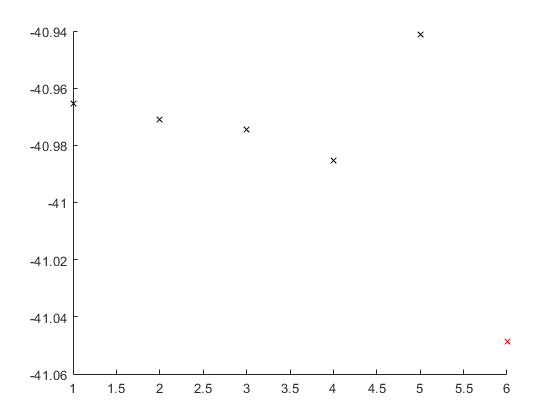

    MFP(i)      = xps_fit.fits{i}.MFP;
    BOFF(i)     = xps_fit.fits{i}.BOFF;
    DCL(i)      = xps_fit.fits{i}.DCL(1);
    CHISQ(i)    = xps_fit.fits{i}.CHISQ;
end
% Isolating any potential outliers
XX              = 1:length(BOFF);
TF              = isoutlier(BOFF);
BOFF_adj{1}     = BOFF(~TF);
BOFF_adj{2}     = BOFF(TF);
XX_adj{1}       = XX(~TF);
XX_adj{2}       = XX(TF);
% -- Plotting the result of outlier analysis
figure(); hold on;
plot(XX_adj{1}, BOFF_adj{1}, 'kx');
plot(XX_adj{2}, BOFF_adj{2}, 'rx');
% -- Redefining variables
MFP         = MFP(~TF);
BOFF        = BOFF(~TF);

DCL         = DCL(~TF);
CHISQ       = CHISQ(~TF);
% -- Band-offset determination
MFP_mu      = mean(MFP)
MFP_3sig    = 3*std(MFP)
BOFF_mu     = mean(BOFF)

MFP_mu = 2.0703

BOFF_3sig   = 3*std(BOFF)

MFP_3sig = 0.8736

DCL_mu      = mean(DCL)

DCL_mu = -40.9675

DCL_3sig    = 3*std(DCL)

DCL_3sig = 0.0489

CHISQ_mu    = mean(CHISQ)

CHISQ_mu = 0.7356

CHISQ_3sig  = 3*std(CHISQ)

CHISQ_3sig = 1.7782

**(F) -  Saving the XPS data & fit results**

-> saved data : 


dataStr = struct with fields:
             filename: "id20210603_M0322211_hvAs3d_FitCL2POT"
           fit_method: "FitCL2POT"
          beamtime_id: "20210603"
           dataset_id: "GaAs Etch Stop Set"
            sample_id: "M03-22-21.1"
    sample_stack_info: "AlOx [2.5 nm] / Al [4 nm] / GaAs [2ML] / InAlAs(10pc) [8.4 nm] "
    repeated_measures: 6
             xps_data: {1×6 cell}
             xps_fits: {1×6 cell}
                  MFP: [1.6984 1.8881 2.0738 2.2560 2.4352]
               MFP_mu: 2.0703
             MFP_3sig: 0.8736
                  DCL: [-40.9652 -40.9709 -40.9746 -40.9852 -40.9414]
               DCL_mu: -40.9675
             DCL_3sig: 0.0489
                CHISQ: [0.2642 0.4244 1.2201 1.5199 0.2494]
             CHISQ_mu: 0.7356
           CHISQ_3sig: 1.7782

% Defining the MATLAB data structure
id20210603_M0322211_hvAs3d_FitCL2BOFF                         = struct();
% - Measurement / Sample Information
id20210603_M0322211_hvAs3d_FitCL2BOFF.filename                = filename+"_"+"FitCL2BOFF";
id20210603_M0322211_hvAs3d_FitCL2BOFF.fit_method              = "FitCL2BOFF";
id20210603_M0322211_hvAs3d_FitCL2BOFF.beamtime_id             = beamtime_id;
id20210603_M0322211_hvAs3d_FitCL2BOFF.dataset_id              = dataset_id;
id20210603_M0322211_hvAs3d_FitCL2BOFF.sample_id               = sample_id;
id20210603_M0322211_hvAs3d_FitCL2BOFF.sample_stack_info       = sample_stack_info;
% - SX-ARPES Data & Fits
id20210603_M0322211_hvAs3d_FitCL2BOFF.repeated_measures       = length(xps_fit.data);
id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_data                = xps_fit.data;
id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits                = xps_fit.fits;
% - Best Fit Results
% -- MFP estimates & measurement uncertainty
id20210603_M0322211_hvAs3d_FitCL2BOFF.MFP                     = MFP;
id20210603_M0322211_hvAs3d_FitCL2BOFF.MFP_mu                  = MFP_mu;
id20210603_M0322211_hvAs3d_FitCL2BOFF.MFP_3sig                = MFP_3sig;
% -- BOFF estimates & measurement uncertainty
id20210603_M0322211_hvAs3d_FitCL2BOFF.BOFF                    = BOFF;
id20210603_M0322211_hvAs3d_FitCL2BOFF.BOFF_mu                 = BOFF_mu;
id20210603_M0322211_hvAs3d_FitCL2BOFF.BOFF_3sig               = BOFF_3sig;
% -- DCL estimates & measurement uncertainty
id20210603_M0322211_hvAs3d_FitCL2BOFF.DCL                     = DCL;
id20210603_M0322211_hvAs3d_FitCL2BOFF.DCL_mu                  = DCL_mu;
id20210603_M0322211_hvAs3d_FitCL2BOFF.DCL_3sig                = DCL_3sig;
% -- CHISQ estimates & measurement uncertainty
id20210603_M0322211_hvAs3d_FitCL2BOFF.CHISQ                   = CHISQ;

id20210603_M0322211_hvAs3d_FitCL2BOFF.CHISQ_mu                = CHISQ_mu;

id20210603_M0322211_hvAs3d_FitCL2POT = struct with fields:
             filename: "id20210603_M0322211_hvAs3d_FitCL2POT"
           fit_method: "FitCL2POT"
          beamtime_id: "20210603"
           dataset_id: "GaAs Etch Stop Set"
            sample_id: "M03-22-21.1"
    sample_stack_info: "AlOx [2.5 nm] / Al [4 nm] / GaAs [2ML] / InAlAs(10pc) [8.4 nm] "
    repeated_measures: 6
             xps_data: {1×6 cell}
             xps_fits: {1×6 cell}
                  MFP: [1.6984 1.8881 2.0738 2.2560 2.4352]
               MFP_mu: 2.0703
             MFP_3sig: 0.8736
                  DCL: [-40.9652 -40.9709 -40.9746 -40.9852 -40.9414]
               DCL_mu: -40.9675
             DCL_3sig: 0.0489
                CHISQ: [0.2642 0.4244 1.2201 1.5199 0.2494]
             CHISQ_mu: 0.7356
           CHISQ_3sig: 1.7782

id20210603_M0322211_hvAs3d_FitCL2BOFF.CHISQ_3sig              = CHISQ_3sig;
% - Saving the data
save_adress_data(id20210603_M0322211_hvAs3d_FitCL2BOFF, save_path + id20210603_M0322211_hvAs3d_FitCL2BOFF.filename);
id20210603_M0322211_hvAs3d_FitCL2BOFF

**(G) -  Saving the corresponding figure & text file with fit results**

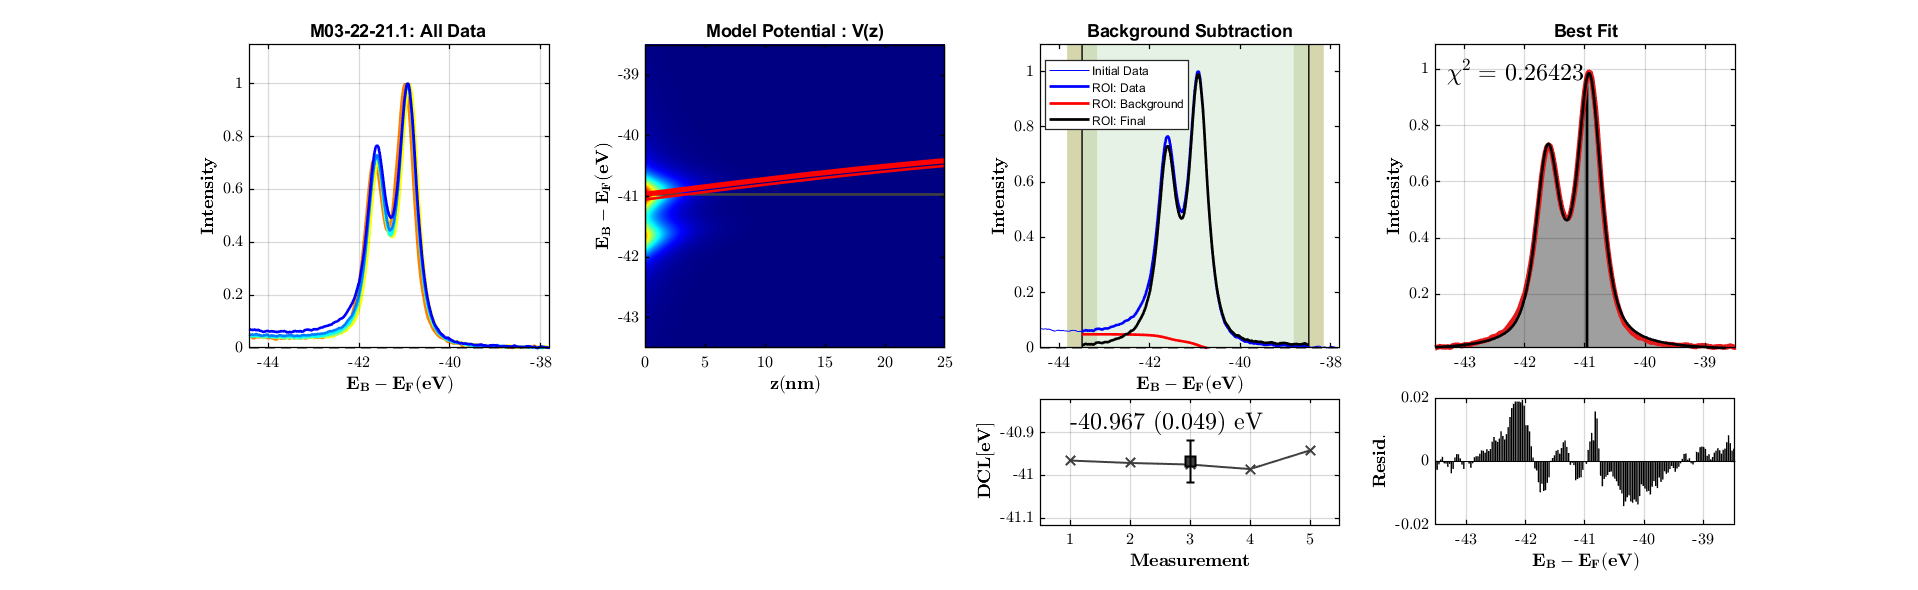

% Initialising the figure
pp  = plot_props();
fig = figure();
fig.Position(3) = 6.5*pp.fig5x4(1);
fig.Position(4) = 2.5*pp.fig5x4(2);
index = 1;

% (1) PLOTTING ALL OF THE XPS DATA
subplot(3,4,[1,5]); hold on;
cols = jet(id20210603_M0322211_hvAs3d_FitCL2BOFF.repeated_measures);
for i = id20210603_M0322211_hvAs3d_FitCL2BOFF.repeated_measures:-1:1
    plot(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_data{i}.xdat, id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_data{i}.ydat, 'k-', 'color', cols(i,:), 'linewidth', 2);
end
axis([min(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_data{1}.xdat(:)), max(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_data{1}.xdat(:)),0, 1.15*max(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_data{1}.ydat(:))]);
title(sprintf(id20210603_M0322211_hvAs3d_FitCL2BOFF.sample_id+": All Data "));
% - Formatting the figure
gca_props(); grid on;
ylabel('$$ \bf  Intensity $$', 'Interpreter', 'latex');
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');

% (2) PLOTTING THE POTENTIAL PROFILE
subplot(3,4,[2,6]); hold on;
ImData(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.ZPOT, id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.XX, id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.potYY_tot);
% -- Plotting the curve component energy locations
for i = 1:id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.nSTATES
    if i == 1; lWidth = pp.llwidth; else; lWidth = pp.lwidth; end
    % --- Plotting DCL
    line([0, max(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.ZPOT(:))], [1,1]*id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.DCL(i), 'Color', pp.col.fit{i}, 'LineWidth', lWidth, 'Linestyle', '-');
    % --- Plotting BE_Z0
    line([0, max(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.ZPOT(:))], [1,1]*id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.BE_Z0(i), 'Color', pp.col.fit{i}, 'LineWidth', lWidth, 'Linestyle', ':');
end
% --- Plotting the potential energy curves
for i = 1:length(xps_fit.fits)
    plot(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{i}.ZPOT, id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{i}.EPOT+id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{i}.DCL(1), 'r-', 'linewidth', 2);
end
% --- Formatting the figure
img_props(); colormap jet; title('Model Potential : V(z)', 'Interpreter','none');
xlabel('$$ \bf  z (nm) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
axis([0, max(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.ZPOT(:)), min(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.XX(:)), max(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.XX(:))]);

% (3) PLOTTING THE XPS DATA AND BACKGROUND
subplot(3,4,[3,7]); hold on;
% -- Plotting the ROI, LHS and RHS analysis windows
ROI     = [id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.X(1), id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.X(end)]; 
LHS     = ROI(1) + 0.05.*[-1,1].*range(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.xdat(:));
RHS     = ROI(2) + 0.05.*[-1,1].*range(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.xdat(:));
hLHS    = patch([LHS(1), LHS(1), LHS(2), LHS(2), LHS(1)], [-1, 1, 1, -1, -1].*1e6, [0.6 0.6 0.2], 'facealpha', 0.4, 'edgecolor', 'none');
hLHS.Annotation.LegendInformation.IconDisplayStyle = 'off';
hRHS    = patch([RHS(1), RHS(1), RHS(2), RHS(2), RHS(1)], [-1, 1, 1, -1, -1].*1e6, [0.6 0.6 0.2], 'facealpha', 0.4, 'edgecolor', 'none');
hRHS.Annotation.LegendInformation.IconDisplayStyle = 'off';
hMID    = patch([ROI(1), ROI(1), ROI(2), ROI(2), ROI(1)], [-1, 1, 1, -1, -1].*1e6, [0.8 0.9 0.8], 'facealpha', 0.5, 'edgecolor', 'none');
hMID.Annotation.LegendInformation.IconDisplayStyle = 'off';
% -- Plotting a vertical line to show the ROI
a = line([ROI(1) ROI(1)], [-1e5, 1e5], 'Color', [0 0 0], 'LineWidth', 1, 'Linestyle', '-');
a.Annotation.LegendInformation.IconDisplayStyle = 'off';
b = line([ROI(2) ROI(2)], [-1e5, 1e5], 'Color', [0 0 0], 'LineWidth', 1, 'Linestyle', '-');
b.Annotation.LegendInformation.IconDisplayStyle = 'off';
% -- Plotting the 1D data
plot(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.xdat, id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.ydat, 'b-', 'linewidth', 0.5);
plot(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.X, id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.D, 'b-', 'linewidth', 2);
plot(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.X, id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.B, 'r-', 'linewidth', 2);
plot(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.X, id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.DB, 'k-', 'linewidth', 2);
gca_props(); title('Background Subtraction', 'interpreter', 'none', 'fontsize', 9); 
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Intensity$$', 'Interpreter', 'latex');
legend({'Initial Data', 'ROI: Data', 'ROI: Background', 'ROI: Final'}, 'location', 'best', 'fontsize', 9);
% -- Determining the best limits for the plot
axLim_y = [id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.ydat; id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.DB];
axis([min(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.xdat(:)), max(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.xdat(:)), min(axLim_y(:)), 1.1*max(axLim_y(:))]);

% (4) PLOTTING THE BEST FIT TO THE XPS DATA
subplot(3,4,[4,8]); hold on;
% -- Plotting all of the curve components
for i = 1:id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.nSTATES
    area(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.XX, id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.cYY(:,i), 'FaceColor', pp.col.fit{i}, 'FaceAlpha', pp.falpha, 'EdgeAlpha', 0);
    plot(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.XX, id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.cYY(:,i), 'k-', 'linewidth', 0.25);
end
% -- Plotting the curve component energy locations
for i = 1:id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.nSTATES
    if i == 1; lWidth = pp.llwidth; else; lWidth = pp.lwidth; end
    % --- Plotting DCL
    line([1,1]*id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.DCL(i), [0, max(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.cYY(:,i))], 'Color', [0 0 0], 'LineWidth', lWidth, 'Linestyle', '-');
    % --- Plotting BE_Z0
    line([1,1]*id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.BE_Z0(i), [0, max(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.cYY(:,i))], 'Color', [0 0 0], 'LineWidth', lWidth, 'Linestyle', ':');
end
% -- Plotting the experimental and fit spectra
plot(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.X, id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.DB, 'k-', 'color', pp.col.dat{1}, 'linewidth', 2*pp.llwidth);
plot(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.X, id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.M, 'k-', 'Color', pp.col.dat{2}, 'linewidth', 2*pp.lwidth);
% -- Add annotation for the quality of fit
text(0.04, 0.90, "$$ \chi^2 = $$ " + string(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.CHISQ),...
    'interpreter', 'latex', 'fontsize', 18, 'color', 'k', 'Units','normalized');
% - Formatting the figure
gca_props(); grid on;
ylabel('$$ \bf  Intensity$$', 'Interpreter', 'latex');
axis([min(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.X(:)), max(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.X(:)), min(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.DB(:)), 1.10*max(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.DB(:))]);
title("Best Fit", 'interpreter', 'none', 'fontsize', 9);

% (5) PLOTTING THE CHI-SQUARED OF BEST FIT
subplot(3,4,12); hold on;
bar(id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.X, id20210603_M0322211_hvAs3d_FitCL2BOFF.xps_fits{index}.R, 'facecolor', [0 0 0]);
gca_props(); grid on;
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Resid. $$', 'Interpreter', 'latex');

% (6) PLOTTING DCL VS MEASUREMENT NUMBER
subplot(3,4,11); hold on;
% Plotting DCL vs measurement number
XX = 1:length(id20210603_M0322211_hvAs3d_FitCL2BOFF.DCL);
plot(XX, id20210603_M0322211_hvAs3d_FitCL2BOFF.DCL, 'kx-', 'color', pp.col.fit{1}, 'markerfacecolor', pp.col.fit{1}, 'linewidth', 1.5,'markersize', 10);
errorbar(mean(XX(:)), id20210603_M0322211_hvAs3d_FitCL2BOFF.DCL_mu, id20210603_M0322211_hvAs3d_FitCL2BOFF.DCL_3sig, id20210603_M0322211_hvAs3d_FitCL2BOFF.DCL_3sig, 0, 0, 'ks-',...
    'color', [0 0 0], 'markerfacecolor', pp.col.fit{1}, 'markersize', 10, 'linewidth', 1.5);
% -- Formatting the figure
grid on; gca_props();
axis([0.5, max(XX)+0.5, id20210603_M0322211_hvAs3d_FitCL2BOFF.DCL_mu-id20210603_M0322211_hvAs3d_FitCL2BOFF.DCL_3sig-0.1, id20210603_M0322211_hvAs3d_FitCL2BOFF.DCL_mu+id20210603_M0322211_hvAs3d_FitCL2BOFF.DCL_3sig+0.1]);
xlabel('$$ \bf  Measurement $$', 'Interpreter', 'latex');
ylabel('$$ \bf  DCL [eV]  $$', 'Interpreter', 'latex');
DCL_str = string(round(id20210603_M0322211_hvAs3d_FitCL2BOFF.DCL_mu,3)) + " (" + string(round(id20210603_M0322211_hvAs3d_FitCL2BOFF.DCL_3sig,3)) + ") eV";
text(0.1,0.8,DCL_str,'Interpreter',"latex",'Units',"normalized",'FontSize',18);


% (7) PLOTTING DCL VS MEASUREMENT NUMBER
subplot(3,4,10); hold on;
% Plotting DCL vs measurement number
XX = 1:length(id20210603_M0322211_hvAs3d_FitCL2BOFF.BOFF);
plot(XX, id20210603_M0322211_hvAs3d_FitCL2BOFF.BOFF, 'kx-', 'color', pp.col.fit{1}, 'markerfacecolor', pp.col.fit{1}, 'linewidth', 1.5,'markersize', 10);
errorbar(mean(XX(:)), id20210603_M0322211_hvAs3d_FitCL2BOFF.BOFF_mu, id20210603_M0322211_hvAs3d_FitCL2BOFF.BOFF_3sig, id20210603_M0322211_hvAs3d_FitCL2BOFF.BOFF_3sig, 0, 0, 'ks-',...
    'color', [0 0 0], 'markerfacecolor', pp.col.fit{1}, 'markersize', 10, 'linewidth', 1.5);
% -- Formatting the figure
grid on; gca_props();
axis([0.5, max(XX)+0.5, id20210603_M0322211_hvAs3d_FitCL2BOFF.BOFF_mu-id20210603_M0322211_hvAs3d_FitCL2BOFF.BOFF_3sig-0.1, id20210603_M0322211_hvAs3d_FitCL2BOFF.BOFF_mu+id20210603_M0322211_hvAs3d_FitCL2BOFF.BOFF_3sig+0.1]);
xlabel('$$ \bf  Measurement $$', 'Interpreter', 'latex');
ylabel('$$ \bf  BOFF [eV]  $$', 'Interpreter', 'latex');
BOFF_str = string(round(id20210603_M0322211_hvAs3d_FitCL2BOFF.BOFF_mu,3)) + " (" + string(round(id20210603_M0322211_hvAs3d_FitCL2BOFF.BOFF_3sig,3)) + ") eV";
text(0.1,0.8,BOFF_str,'Interpreter',"latex",'Units',"normalized",'FontSize',18);


Filename: 		 id20210603_M0322211_hvAs3d_FitCL2POT 
Fit Method: 	 FitCL2POT 
Sample ID: 		 M03-22-21.1 
Sample stack: 	 AlOx [2.5 nm] / Al [4 nm] / GaAs [2ML] / InAlAs(10pc) [8.4 nm]  
Beamtime ID: 	 20210603 
Repeats: 		 6 
MFP: 			 2.070 (0.874) nm 
DCL: 			 -40.967 (0.049) eV 
CHISQ: 		 0.736 (1.778) 
Notes: 		 

% (8) SAVING THE FIGURE
print(save_path + id20210603_M0322211_hvAs3d_FitCL2BOFF.filename,'-dpng', '-r500');

% (9) SAVING A TEXT FILE
% -- Creating an information string
info = "";
info = info + sprintf("Filename: \t\t %s \n",             id20210603_M0322211_hvAs3d_FitCL2BOFF.filename);
info = info + sprintf("Fit Method: \t %s \n",           id20210603_M0322211_hvAs3d_FitCL2BOFF.fit_method);
info = info + sprintf("Sample ID: \t\t %s \n",            id20210603_M0322211_hvAs3d_FitCL2BOFF.sample_id);
info = info + sprintf("Sample stack: \t %s \n",         id20210603_M0322211_hvAs3d_FitCL2BOFF.sample_stack_info);
info = info + sprintf("Beamtime ID: \t %s \n",          id20210603_M0322211_hvAs3d_FitCL2BOFF.beamtime_id);
info = info + sprintf("Repeats: \t\t %i \n",              id20210603_M0322211_hvAs3d_FitCL2BOFF.repeated_measures);
info = info + sprintf("MFP: \t\t\t %.3f (%.3f) nm \n",    id20210603_M0322211_hvAs3d_FitCL2BOFF.MFP_mu, id20210603_M0322211_hvAs3d_FitCL2BOFF.MFP_3sig);
info = info + sprintf("BOFF: \t\t %.3f (%.3f) eV \n",   id20210603_M0322211_hvAs3d_FitCL2BOFF.BOFF_mu, id20210603_M0322211_hvAs3d_FitCL2BOFF.BOFF_3sig);
info = info + sprintf("DCL: \t\t\t %.3f (%.3f) eV \n",    id20210603_M0322211_hvAs3d_FitCL2BOFF.DCL_mu, id20210603_M0322211_hvAs3d_FitCL2BOFF.DCL_3sig);
info = info + sprintf("CHISQ: \t\t %.3f (%.3f) \n",     id20210603_M0322211_hvAs3d_FitCL2BOFF.CHISQ_mu, id20210603_M0322211_hvAs3d_FitCL2BOFF.CHISQ_3sig);
info = info + sprintf("Notes: \t\t %s", measurement_notes);
fprintf(info);
% -- Writing the string to a text file
fileID = fopen(char(save_path + id20210603_M0322211_hvAs3d_FitCL2BOFF.filename + ".txt"),'w');
fprintf(fileID,info);
fclose(fileID);

# **(2.4) FitCL2POT: XPS Curve Fitting based on a pre-defined potential well**

**(A) Initialising the XPS data to be fitted**

xps_fit               = struct();
xps_fit.FileName      = file_names;
xps_fit.repeats       = length(xps_fit);
xps_fit.data          = xps_dat;

**(B) Extracting the IMFP**

% - 1 - Extracting the material parameters from the materials database
material        = 'GaN';
material_props  = get_mpd_props(material);
Wfunc           = material_props.ELE_WFUNC;
% - 2 - Determination of the IMFP TPP-2M
hv = []; ke_dat = []; IMFP = [];
for i = 1:length(xps_fit.data) 
    hv(i)       = xps_fit.data{i}.hv;
    ke_dat(i)   = hv(i) - Wfunc;
    IMFP(i)     = eimfp_tpp2m_mpd(ke_dat(i), material);
end
hv
IMFP    = 0.1*IMFP          % - Convert IMFP to nm

**(C) Defining the initial conditions & bounds for the model fit**

help PESCurve_POT;
% DEFINING THE TYPES OF CURVES TO BE USED
cTYPE   = ["sGLA"];  % type of curve to use for fitting. Default: "sGLA" ("pGLA", "DS")
ZPOT    = linspace(0, 25, 500);                            % 1xN array of the z-domain (depth) of the potential profile [eV]
EPOT    = 1.0*(1./(1 + exp(-ZPOT*0.05)) - 0.5) / 0.5;      % 1xN array of the potential energy relative to the Fermi-level [eV]
% 1.1 - DEFINING THE INITIAL CONDITIONS OF THE XPS COMPONENTS
DCL      = [-40.882];        % scalar of the binding energy of PE curve. Each new row gives a new BE component. Make sure sizes are all consistent.
INT     = [1.07];          % scalar of the peak intensity of PE curve.
FWHM    = [0.48];          % scalar of the FWHM of the PE curve.
MR      = [0.69];          % scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
LSE     = [-0.69];         % scalar of the binding energy of spin-orbit split PE curve.
LSI     = [0.66];          % scalar of the branching ratio of spin-orbit split PE curve.
LSW     = [0.00];          % scalar of the additional lorentzian width of spin-orbit split PE curve.
ASY     = [0.00];          % scalar of the PE curve asymmetry parameter (usually for metallic systems).
iparams{1} = [DCL, INT, FWHM, MR, LSE, LSI, LSW, ASY]; 
iparams{1}
% 1.2 - DEFINING THE UNCERTAINTIES IN THE FIT PARAMETERS
% -- Lower bounds
iparams{2} = iparams{1}; 
iparams{2}(:,1) = iparams{1}(:,1) - 0.25;
iparams{2}(:,2) = iparams{1}(:,2) - 1.00;
iparams{2}(:,3) = iparams{1}(:,3) - 0.25; 
iparams{2}(:,4) = iparams{1}(:,4) - 0.25; 
iparams{2}(:,5) = iparams{1}(:,5) - 0.15; 
iparams{2}(:,6) = iparams{1}(:,6) - 0.15; 
iparams{2}(:,7) = iparams{1}(:,7) - 0.00; 
iparams{2}(:,8) = iparams{1}(:,8) - 0.00;
iparams{2}
% -- Upper bounds
iparams{3}      = iparams{1}; 
iparams{3}(:,1) = iparams{1}(:,1) + 0.25; 
iparams{3}(:,2) = iparams{1}(:,2) + 0.50;
iparams{3}(:,3) = iparams{1}(:,3) + 0.25; 
iparams{3}(:,4) = iparams{1}(:,4) + 0.25; 
iparams{3}(:,5) = iparams{1}(:,5) + 0.15; 
iparams{3}(:,6) = iparams{1}(:,6) + 0.15; 
iparams{3}(:,7) = iparams{1}(:,7) + 0.00; 
iparams{3}(:,8) = iparams{1}(:,8) + 0.00;
iparams{3}

% 2.1 - DEFINING THE BACKGROUND PARAMETERS
bTYPE   = "shir";       % type of background to use for fitting. Default: "Poly" ("none", "Shir", "LinShir")
LHS     = -43.5;      % scalar of the START point on the LHS for background
RHS     = -38.5;      % scalar of the END point on the RHS for background
BGR     = 0.00;      % scalar for a constant background to be included in the fit
ibgrnd{1} = [LHS, RHS, BGR]; 
ibgrnd{1}
% 2.2 - DEFINING THE UNCERTAINTY IN THE BACKGROUND PARAMETERS
% -- Lower bounds
ibgrnd{2} = abs(0.0.*ibgrnd{1}); 
ibgrnd{2}(:,1) = ibgrnd{1}(:,1) - 0.00;
ibgrnd{2}(:,2) = ibgrnd{1}(:,2) - 0.00;
ibgrnd{2}(:,3) = ibgrnd{1}(:,3) - 0.05;
ibgrnd{2}
% -- Upper bounds
ibgrnd{3} = abs(0.0.*ibgrnd{1}); 
ibgrnd{3}(:,1) = ibgrnd{1}(:,1) + 0.00;
ibgrnd{3}(:,2) = ibgrnd{1}(:,2) + 0.00;
ibgrnd{3}(:,3) = ibgrnd{1}(:,3) + 0.05;
ibgrnd{3}
% 2.3 - DEFINING THE BACKGROUND ARGUMENTS
ibgrnd{4} = {};

% 3 - Preview the initial conditions of the model vs data fit
pes2pot_view_init(xps_fit.data{end}, cTYPE, iparams, bTYPE, ibgrnd, IMFP(end), ZPOT, EPOT);

**(D) Execute XPS fitting algorithm**

solve_type  = "lsqcurvefit";
for i = 1:length(xps_fit.data)
    fprintf("Run %i / %i", i, length(xps_fit.data));
    xps_fit.fits{i} = pes2pot_solver(xps_fit.data{i}, cTYPE, iparams, bTYPE, ibgrnd, solve_type, IMFP(i), ZPOT, EPOT);
end
pes2pot_view_fit(xps_fit.fits{1}); xps_fit.fits{1}
pes2pot_view_fit(xps_fit.fits{end}); xps_fit.fits{end}

**(E) Finding the best estimate of BOFF across the dataset**

DCL = []; MFP = []; CHISQ = [];
for i = 1:length(xps_fit.fits)
    MFP(i)      = xps_fit.fits{i}.MFP;
    DCL(i)      = xps_fit.fits{i}.DCL(1);
    CHISQ(i)    = xps_fit.fits{i}.CHISQ;
end
% Isolating any potential outliers
XX              = 1:length(DCL);
TF              = isoutlier(DCL);
BE_adj{1}       = DCL(~TF);
BE_adj{2}       = DCL(TF);
XX_adj{1}       = XX(~TF);
XX_adj{2}       = XX(TF);
% -- Plotting the result of outlier analysis
figure(); hold on;
plot(XX_adj{1}, BE_adj{1}, 'kx');
plot(XX_adj{2}, BE_adj{2}, 'rx');
% -- Redefining variables
MFP         = MFP(~TF);
DCL         = DCL(~TF);
CHISQ       = CHISQ(~TF);
% -- Band-offset determination
MFP_mu      = mean(MFP)
MFP_3sig    = 3*std(MFP)
DCL_mu      = mean(DCL)
DCL_3sig    = 3*std(DCL)
CHISQ_mu    = mean(CHISQ)
CHISQ_3sig  = 3*std(CHISQ)

**(F) -  Saving the XPS data & fit results**

% Defining the MATLAB data structure
id20210603_M0322211_hvAs3d_FitCL2POT                         = struct();
% - Measurement / Sample Information
id20210603_M0322211_hvAs3d_FitCL2POT.filename                = filename+"_"+"FitCL2POT";
id20210603_M0322211_hvAs3d_FitCL2POT.fit_method              = "FitCL2POT";
id20210603_M0322211_hvAs3d_FitCL2POT.beamtime_id             = beamtime_id;
id20210603_M0322211_hvAs3d_FitCL2POT.dataset_id              = dataset_id;
id20210603_M0322211_hvAs3d_FitCL2POT.sample_id               = sample_id;
id20210603_M0322211_hvAs3d_FitCL2POT.sample_stack_info       = sample_stack_info;
% - SX-ARPES Data & Fits
id20210603_M0322211_hvAs3d_FitCL2POT.repeated_measures       = length(xps_fit.data);
id20210603_M0322211_hvAs3d_FitCL2POT.xps_data                = xps_fit.data;
id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits                = xps_fit.fits;
% - Best Fit Results
% -- MFP estimates & measurement uncertainty
id20210603_M0322211_hvAs3d_FitCL2POT.MFP                     = MFP;
id20210603_M0322211_hvAs3d_FitCL2POT.MFP_mu                  = MFP_mu;
id20210603_M0322211_hvAs3d_FitCL2POT.MFP_3sig                = MFP_3sig;
% -- DCL estimates & measurement uncertainty
id20210603_M0322211_hvAs3d_FitCL2POT.DCL                     = DCL;
id20210603_M0322211_hvAs3d_FitCL2POT.DCL_mu                  = DCL_mu;
id20210603_M0322211_hvAs3d_FitCL2POT.DCL_3sig                = DCL_3sig;
% -- CHISQ estimates & measurement uncertainty
id20210603_M0322211_hvAs3d_FitCL2POT.CHISQ                   = CHISQ;
id20210603_M0322211_hvAs3d_FitCL2POT.CHISQ_mu                = CHISQ_mu;
id20210603_M0322211_hvAs3d_FitCL2POT.CHISQ_3sig              = CHISQ_3sig;
% - Saving the data
save_adress_data(id20210603_M0322211_hvAs3d_FitCL2POT, save_path + id20210603_M0322211_hvAs3d_FitCL2POT.filename);
id20210603_M0322211_hvAs3d_FitCL2POT

**(G) -  Saving the corresponding figure & text file with fit results**

% Initialising the figure
pp  = plot_props();
fig = figure();
fig.Position(3) = 6.5*pp.fig5x4(1);
fig.Position(4) = 2.5*pp.fig5x4(2);
index = 1;

% (1) PLOTTING ALL OF THE XPS DATA
subplot(3,4,[1,5]); hold on;
cols = jet(id20210603_M0322211_hvAs3d_FitCL2POT.repeated_measures);
for i = id20210603_M0322211_hvAs3d_FitCL2POT.repeated_measures:-1:1
    plot(id20210603_M0322211_hvAs3d_FitCL2POT.xps_data{i}.xdat, id20210603_M0322211_hvAs3d_FitCL2POT.xps_data{i}.ydat, 'k-', 'color', cols(i,:), 'linewidth', 2);
end
axis([min(id20210603_M0322211_hvAs3d_FitCL2POT.xps_data{1}.xdat(:)), max(id20210603_M0322211_hvAs3d_FitCL2POT.xps_data{1}.xdat(:)),0, 1.15*max(id20210603_M0322211_hvAs3d_FitCL2POT.xps_data{1}.ydat(:))]);
title(sprintf(id20210603_M0322211_hvAs3d_FitCL2POT.sample_id+": All Data "));
% - Formatting the figure
gca_props(); grid on;
ylabel('$$ \bf  Intensity $$', 'Interpreter', 'latex');
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');

% (2) PLOTTING THE POTENTIAL PROFILE
subplot(3,4,[2,6]); hold on;
ImData(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.ZPOT, id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.XX, id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.potYY_tot);
% -- Plotting the curve component energy locations
for i = 1:id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.nSTATES
    if i == 1; lWidth = pp.llwidth; else; lWidth = pp.lwidth; end
    % --- Plotting DCL
    line([0, max(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.ZPOT(:))], [1,1]*id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.DCL(i), 'Color', pp.col.fit{i}, 'LineWidth', lWidth, 'Linestyle', '-');
    % --- Plotting BE_Z0
    line([0, max(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.ZPOT(:))], [1,1]*id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.BE_Z0(i), 'Color', pp.col.fit{i}, 'LineWidth', lWidth, 'Linestyle', ':');
end
% --- Plotting the potential energy curves
for i = 1:length(xps_fit.fits)
    plot(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{i}.ZPOT, id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{i}.EPOT+id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{i}.DCL(1), 'r-', 'linewidth', 2);
end
% --- Formatting the figure
img_props(); colormap jet; title('Model Potential : V(z)', 'Interpreter','none');
xlabel('$$ \bf  z (nm) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
axis([0, max(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.ZPOT(:)), min(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.XX(:)), max(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.XX(:))]);

% (3) PLOTTING THE XPS DATA AND BACKGROUND
subplot(3,4,[3,7]); hold on;
% -- Plotting the ROI, LHS and RHS analysis windows
ROI     = [id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.X(1), id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.X(end)]; 
LHS     = ROI(1) + 0.05.*[-1,1].*range(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.xdat(:));
RHS     = ROI(2) + 0.05.*[-1,1].*range(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.xdat(:));
hLHS    = patch([LHS(1), LHS(1), LHS(2), LHS(2), LHS(1)], [-1, 1, 1, -1, -1].*1e6, [0.6 0.6 0.2], 'facealpha', 0.4, 'edgecolor', 'none');
hLHS.Annotation.LegendInformation.IconDisplayStyle = 'off';
hRHS    = patch([RHS(1), RHS(1), RHS(2), RHS(2), RHS(1)], [-1, 1, 1, -1, -1].*1e6, [0.6 0.6 0.2], 'facealpha', 0.4, 'edgecolor', 'none');
hRHS.Annotation.LegendInformation.IconDisplayStyle = 'off';
hMID    = patch([ROI(1), ROI(1), ROI(2), ROI(2), ROI(1)], [-1, 1, 1, -1, -1].*1e6, [0.8 0.9 0.8], 'facealpha', 0.5, 'edgecolor', 'none');
hMID.Annotation.LegendInformation.IconDisplayStyle = 'off';
% -- Plotting a vertical line to show the ROI
a = line([ROI(1) ROI(1)], [-1e5, 1e5], 'Color', [0 0 0], 'LineWidth', 1, 'Linestyle', '-');
a.Annotation.LegendInformation.IconDisplayStyle = 'off';
b = line([ROI(2) ROI(2)], [-1e5, 1e5], 'Color', [0 0 0], 'LineWidth', 1, 'Linestyle', '-');
b.Annotation.LegendInformation.IconDisplayStyle = 'off';
% -- Plotting the 1D data
plot(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.xdat, id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.ydat, 'b-', 'linewidth', 0.5);
plot(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.X, id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.D, 'b-', 'linewidth', 2);
plot(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.X, id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.B, 'r-', 'linewidth', 2);
plot(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.X, id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.DB, 'k-', 'linewidth', 2);
gca_props(); title('Background Subtraction', 'interpreter', 'none', 'fontsize', 9); 
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Intensity$$', 'Interpreter', 'latex');
legend({'Initial Data', 'ROI: Data', 'ROI: Background', 'ROI: Final'}, 'location', 'best', 'fontsize', 9);
% -- Determining the best limits for the plot
axLim_y = [id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.ydat; id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.DB];
axis([min(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.xdat(:)), max(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.xdat(:)), min(axLim_y(:)), 1.1*max(axLim_y(:))]);

% (4) PLOTTING THE BEST FIT TO THE XPS DATA
subplot(3,4,[4,8]); hold on;
% -- Plotting all of the curve components
for i = 1:id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.nSTATES
    area(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.XX, id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.cYY(:,i), 'FaceColor', pp.col.fit{i}, 'FaceAlpha', pp.falpha, 'EdgeAlpha', 0);
    plot(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.XX, id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.cYY(:,i), 'k-', 'linewidth', 0.25);
end
% -- Plotting the curve component energy locations
for i = 1:id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.nSTATES
    if i == 1; lWidth = pp.llwidth; else; lWidth = pp.lwidth; end
    % --- Plotting DCL
    line([1,1]*id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.DCL(i), [0, max(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.cYY(:,i))], 'Color', [0 0 0], 'LineWidth', lWidth, 'Linestyle', '-');
    % --- Plotting BE_Z0
    line([1,1]*id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.BE_Z0(i), [0, max(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.cYY(:,i))], 'Color', [0 0 0], 'LineWidth', lWidth, 'Linestyle', ':');
end
% -- Plotting the experimental and fit spectra
plot(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.X, id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.DB, 'k-', 'color', pp.col.dat{1}, 'linewidth', 2*pp.llwidth);
plot(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.X, id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.M, 'k-', 'Color', pp.col.dat{2}, 'linewidth', 2*pp.lwidth);
% -- Add annotation for the quality of fit
text(0.04, 0.90, "$$ \chi^2 = $$ " + string(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.CHISQ),...
    'interpreter', 'latex', 'fontsize', 18, 'color', 'k', 'Units','normalized');
% - Formatting the figure
gca_props(); grid on;
ylabel('$$ \bf  Intensity$$', 'Interpreter', 'latex');
axis([min(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.X(:)), max(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.X(:)), min(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.DB(:)), 1.10*max(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.DB(:))]);
title("Best Fit", 'interpreter', 'none', 'fontsize', 9);

% (5) PLOTTING THE CHI-SQUARED OF BEST FIT
subplot(3,4,12); hold on;
bar(id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.X, id20210603_M0322211_hvAs3d_FitCL2POT.xps_fits{index}.R, 'facecolor', [0 0 0]);
gca_props(); grid on;
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Resid. $$', 'Interpreter', 'latex');

% (6) PLOTTING DCL VS MEASUREMENT NUMBER
subplot(3,4,11); hold on;
% Plotting DCL vs measurement number
XX = 1:length(id20210603_M0322211_hvAs3d_FitCL2POT.DCL);
plot(XX, id20210603_M0322211_hvAs3d_FitCL2POT.DCL, 'kx-', 'color', pp.col.fit{1}, 'markerfacecolor', pp.col.fit{1}, 'linewidth', 1.5,'markersize', 10);
errorbar(mean(XX(:)), id20210603_M0322211_hvAs3d_FitCL2POT.DCL_mu, id20210603_M0322211_hvAs3d_FitCL2POT.DCL_3sig, id20210603_M0322211_hvAs3d_FitCL2POT.DCL_3sig, 0, 0, 'ks-',...
    'color', [0 0 0], 'markerfacecolor', pp.col.fit{1}, 'markersize', 10, 'linewidth', 1.5);
% -- Formatting the figure
grid on; gca_props();
axis([0.5, max(XX)+0.5, id20210603_M0322211_hvAs3d_FitCL2POT.DCL_mu-id20210603_M0322211_hvAs3d_FitCL2POT.DCL_3sig-0.1, id20210603_M0322211_hvAs3d_FitCL2POT.DCL_mu+id20210603_M0322211_hvAs3d_FitCL2POT.DCL_3sig+0.1]);
xlabel('$$ \bf  Measurement $$', 'Interpreter', 'latex');
ylabel('$$ \bf  DCL [eV]  $$', 'Interpreter', 'latex');
DCL_str = string(round(id20210603_M0322211_hvAs3d_FitCL2POT.DCL_mu,3)) + " (" + string(round(id20210603_M0322211_hvAs3d_FitCL2POT.DCL_3sig,3)) + ") eV";
text(0.1,0.8,DCL_str,'Interpreter',"latex",'Units',"normalized",'FontSize',18);

% (8) SAVING THE FIGURE
print(save_path + id20210603_M0322211_hvAs3d_FitCL2POT.filename,'-dpng', '-r500');

% (9) SAVING A TEXT FILE
% -- Creating an information string
info = "";
info = info + sprintf("Filename: \t\t %s \n",             id20210603_M0322211_hvAs3d_FitCL2POT.filename);
info = info + sprintf("Fit Method: \t %s \n",           id20210603_M0322211_hvAs3d_FitCL2POT.fit_method);
info = info + sprintf("Sample ID: \t\t %s \n",            id20210603_M0322211_hvAs3d_FitCL2POT.sample_id);
info = info + sprintf("Sample stack: \t %s \n",         id20210603_M0322211_hvAs3d_FitCL2POT.sample_stack_info);
info = info + sprintf("Beamtime ID: \t %s \n",          id20210603_M0322211_hvAs3d_FitCL2POT.beamtime_id);
info = info + sprintf("Repeats: \t\t %i \n",              id20210603_M0322211_hvAs3d_FitCL2POT.repeated_measures);
info = info + sprintf("MFP: \t\t\t %.3f (%.3f) nm \n",    id20210603_M0322211_hvAs3d_FitCL2POT.MFP_mu, id20210603_M0322211_hvAs3d_FitCL2POT.MFP_3sig);
info = info + sprintf("DCL: \t\t\t %.3f (%.3f) eV \n",    id20210603_M0322211_hvAs3d_FitCL2POT.DCL_mu, id20210603_M0322211_hvAs3d_FitCL2POT.DCL_3sig);
info = info + sprintf("CHISQ: \t\t %.3f (%.3f) \n",     id20210603_M0322211_hvAs3d_FitCL2POT.CHISQ_mu, id20210603_M0322211_hvAs3d_FitCL2POT.CHISQ_3sig);
info = info + sprintf("Notes: \t\t %s", measurement_notes);
fprintf(info);
% -- Writing the string to a text file
fileID = fopen(char(save_path + id20210603_M0322211_hvAs3d_FitCL2POT.filename + ".txt"),'w');
fprintf(fileID,info);
fclose(fileID);